# **Script to clean and analyze online data**

**NOTE: Edits to the raw data- added the response time column, and made all null responses a -1**

**1. Setup and overall metrics**

clear all
close all

% For plotting
% addpath('C:\Program Files (x86)\piermorel-gramm-b0fc592'); 
addpath('C:\Users\dk00549\OneDrive - University of Surrey\Documents\Surrey\MATLAB\PluginsProgramsToolboxes\gramm-master')
% For emmeans
addpath('C:\Program Files (x86)\jackatta-estimated-marginal-means-915f311')

% For Henry's Violin Plots
addpath('C:\Users\dk00549\OneDrive - University of Surrey\Documents\Surrey\MATLAB\PluginsProgramsToolboxes\violinplot');

%Read in the csvs
df = readtable('rawdata_pilot4.csv');

%Determine how many participants we have
N = size(unique(df.auto_participant_id),1)

N = 87


%Delete participants with fewer than 100 trials
Ntrials = groupcounts(df,{'auto_participant_id'});
dfraw = df;
IDs_delete = Ntrials.auto_participant_id(Ntrials.GroupCount<100) % We now have 80 participants

IDs_delete = 7×1 cell array
    {'307.8449999447912_56668' }
    {'447.29499999812106_93894'}
    {'473.31000003032386_96248'}
    {'573.8550000241958_899'   }
    {'622.304999968037_24532'  }
    {'778.6750000013853_46353' }
    {'839.5149999996647_20820' }


df(ismember(df.auto_participant_id,IDs_delete),:)=[];



**2. Determine Occurrence, Switch Type, and Cue Card length**

% Sorting the rows in df by participant ID, so groupcounts and df are in
% the same order
df = sortrows(df,'auto_participant_id','ascend');
Ntrials = groupcounts(df,{'auto_participant_id'});
trial_vect = cumsum([Ntrials.GroupCount]);

%occurrence = zeros(size(df,1),1);
index = 1;
oc = [];
trial_vect = cumsum([Ntrials.GroupCount]);

%For all the trials per person
for ii=1:size(Ntrials,1)
    
    %if the first trial, 
    if ii==1
        subjtrials = df.trial_task_type(1:trial_vect(ii));
    else
        subjtrials = df.trial_task_type(trial_vect(ii-1)+1:trial_vect(ii));
    end
    
    %n is the number of trials per subject, whereas id are the types of
    %trials- in this case, DS, SS, and SR
    [n, id] = findgroups(subjtrials);
    
    %This is neat- it creates a list where it records whether that trial
    %for that person is of a specific type (true, 1) or not (false, 0)
    type1 = (n==1);
    type2 = (n==2);
    type3 = (n==3);
    
    %create a vector that also counts the "numberOfStreaks", ie,
    %occurrences. This changes the occurrences from just a 1 listing where
    %it would occur to the number representing which occurrence it is.
    [L1, numberOfStreaks1] = bwlabel(type1);
    [L2, numberOfStreaks2] = bwlabel(type2);
    [L3, numberOfStreaks3] = bwlabel(type3);
    
    %Sum the lists
    t = L1+L2+L3;
    oc = [oc; t];
    
end

% Adding occurence to df, and deleting any 10th occurrences (they're too
% rare to count)
df.occurrence = oc;
todelete = df.occurrence > 9 ;
df(todelete,:) = [];

%Determine Switch Type
df = sortrows(df,'auto_participant_id','ascend');

for ii = 2:size(df,1)

            %if participant ID does not change between trials, but task
            %type does, log the task switch
        if strcmpi(df.auto_participant_id(ii),df.auto_participant_id(ii-1))==1 && strcmpi(df.trial_task_type(ii),df.trial_task_type(ii-1))==0
            %concatenate the task trial type previous -2- current         
            switchtype(ii,1) = string(strcat(df.trial_task_type(ii-1),'-2-',df.trial_task_type(ii)));   
  
        end               
end

df.switchtype = switchtype;

% Need to create a "numbered" version of the switchtype so analysis is way
% easier
for ii = 1:size(df,1)
    
        if strcmpi(df.switchtype(ii),"ts-trial-spatial-rotation-2-ts-trial-digit-span")==1        
            NumSwitchtype(ii,1) = 1;   
        elseif strcmpi(df.switchtype(ii),"ts-trial-spatial-rotation-2-ts-trial-spatial-span")==1
            NumSwitchtype(ii,1) = 2; 
        elseif strcmpi(df.switchtype(ii),"ts-trial-spatial-span-2-ts-trial-spatial-rotation")==1
            NumSwitchtype(ii,1) = 3; 
        elseif strcmpi(df.switchtype(ii),"ts-trial-spatial-span-2-ts-trial-digit-span")==1
            NumSwitchtype(ii,1) = 4; 
        elseif strcmpi(df.switchtype(ii),"ts-trial-digit-span-2-ts-trial-spatial-span")==1
            NumSwitchtype(ii,1) = 5; 
        elseif strcmpi(df.switchtype(ii),"ts-trial-digit-span-2-ts-trial-spatial-rotation")==1
            NumSwitchtype(ii,1) = 6; 
        end               
end

df.NumSwitchtype = NumSwitchtype;



**3. Checking data quality and data cleaning**

% Number of trials per participant
Ntrials_participant = groupcounts(df,{'auto_participant_id'});
mean(Ntrials_participant.GroupCount)

ans = 178.8625

std(Ntrials_participant.GroupCount)

ans = 12.3757



%Calculate and plot the number of trials per pilot version (needed in Section 6.1)
Ntrials = groupcounts(df,{'auto_participant_id','trial_task_type', 'occurrence'});
mean(Ntrials.GroupCount)

ans = 7.2598

std(Ntrials.GroupCount)

ans = 1.3651

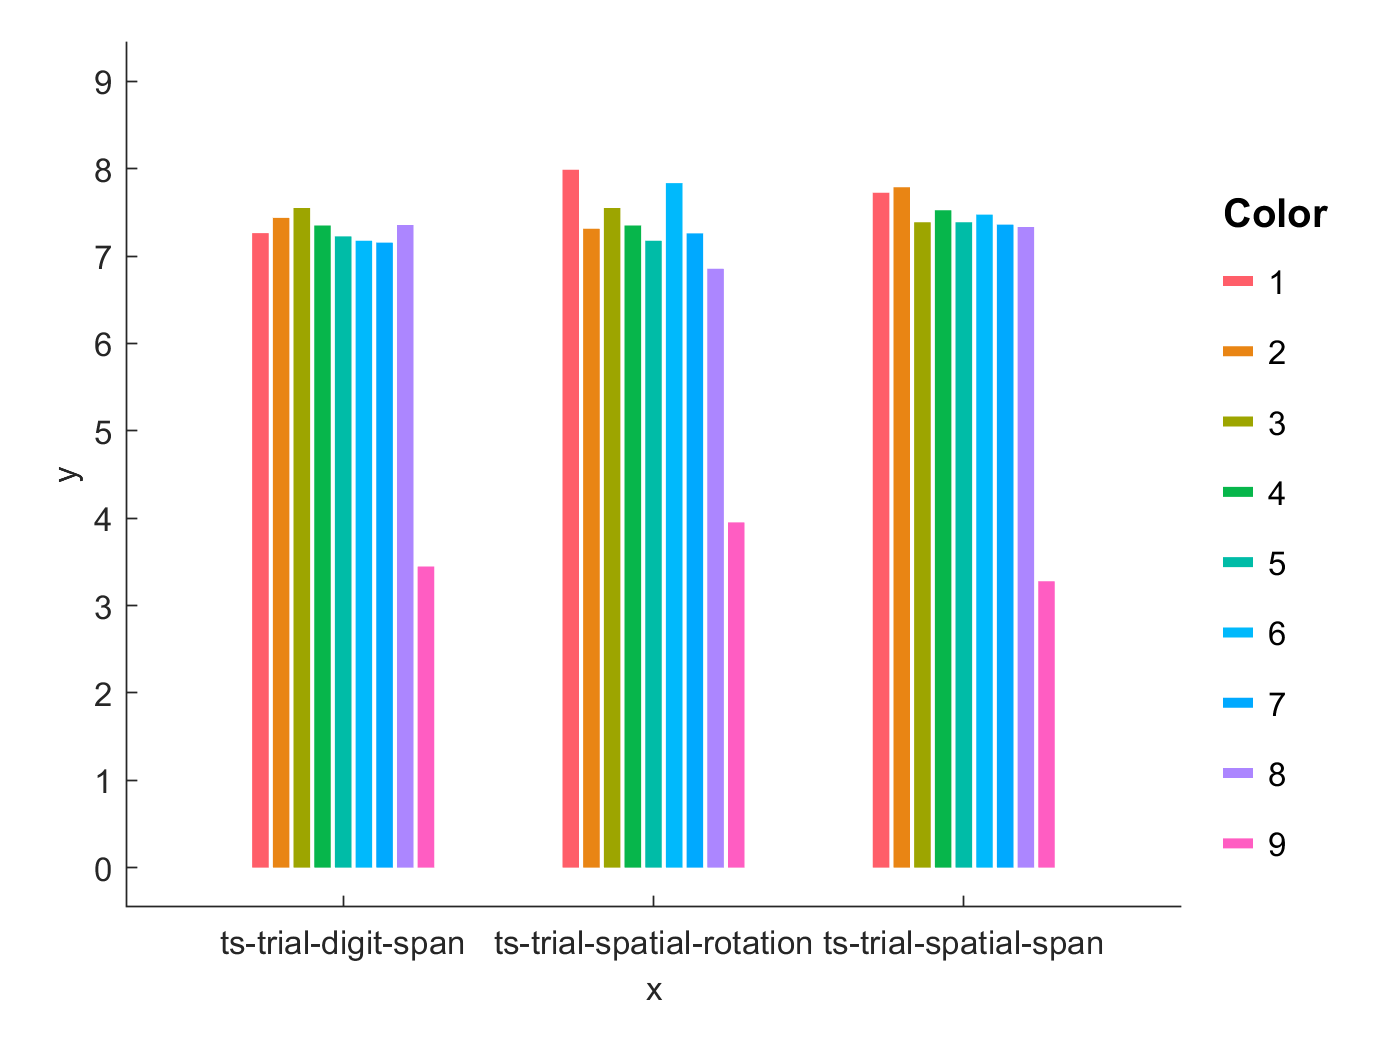

%There's an average of 7.2 trials per occurrence

dt=gramm('x',Ntrials.trial_task_type,'y',Ntrials.GroupCount,'color',Ntrials.occurrence);
dt.stat_summary('geom',{'bar'});
figure
dt.draw();

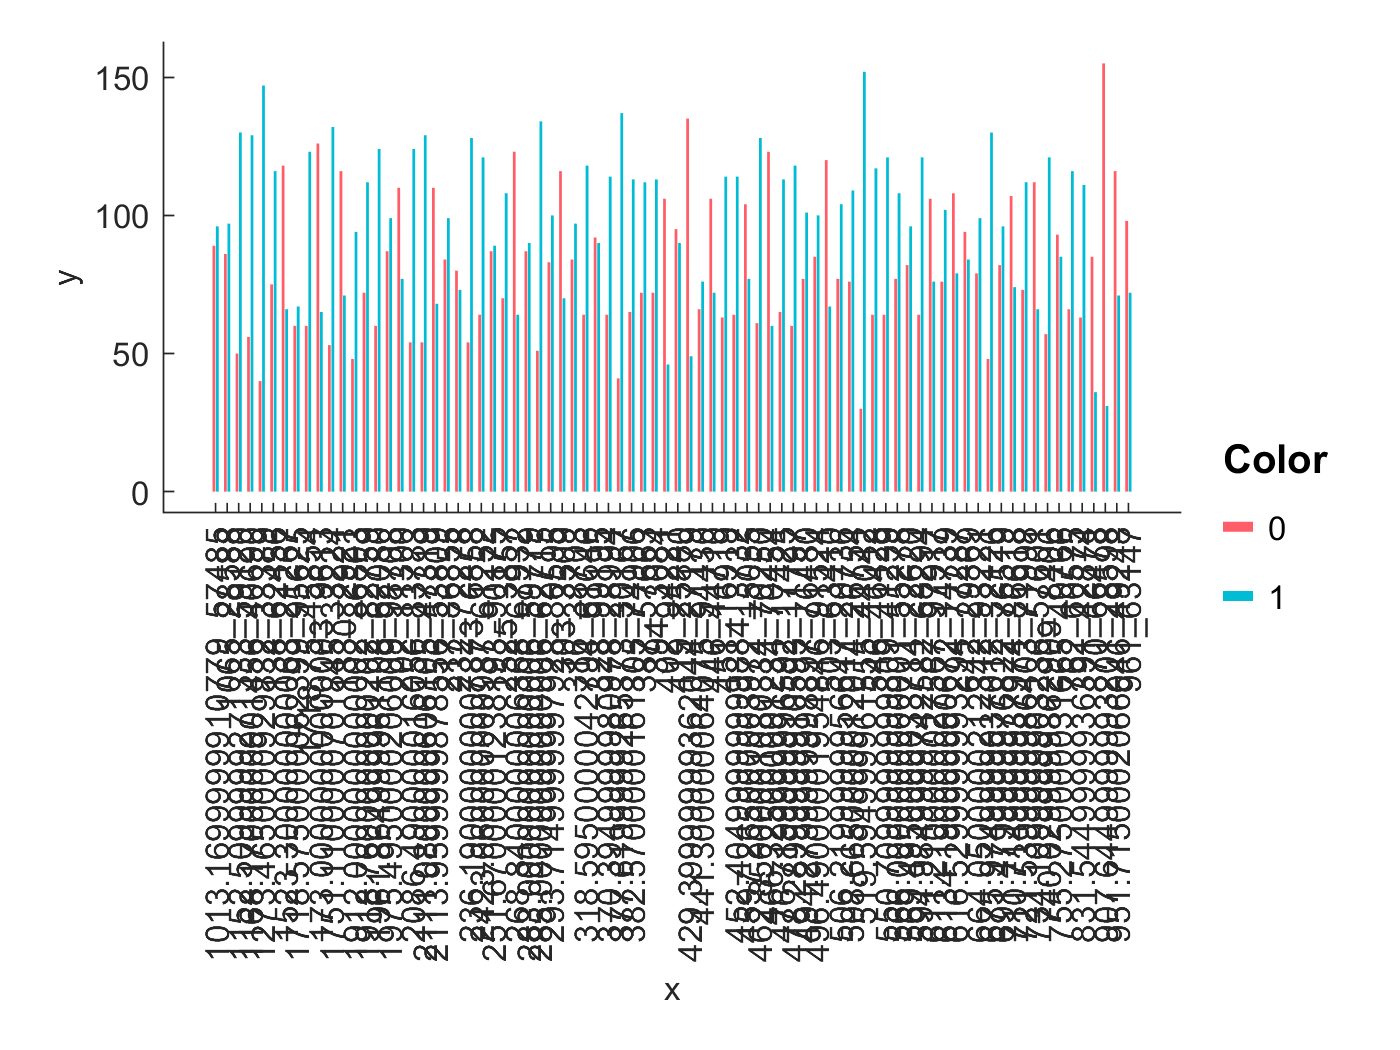

Less than 2 samples for CI computation...Skipping
Less than 2 samples for CI computation...Skipping
Less than 2 samples for CI computation...Skipping
Less than 2 samples for CI computation...Skipping
Less than 2 samples for CI computation...Skipping
Less than 2 samples for CI computation...Skipping
Less than 2 samples for CI computation...Skipping
Less than 2 samples for CI computation...Skipping
Less than 2 samples for CI computation...Skipping
Less than 2 samples for CI computation...Skipping
Less than 2 samples for CI computation...Skipping
Less than 2 samples for CI computation...Skipping
Less than 2 samples for CI computation...Skipping
Less than 2 samples for CI computation...Skipping
Less than 2 samples for CI computation...Skipping
Less than 2 samples for CI computation...Skipping
Less than 2 samples for CI computation...Skipping
Less than 2 samples for CI computation...Skipping
Less than 2 samples for CI computation...Skipping
Less than 2 samples for CI computation...Skipping


%There's a low number of trials for the later occurrences. 
% There's a close to equivalent amount of 9th occurrences across task types, though
% I'm not sure why there's a greater number of occurrences for the spatial
% rotation

%Cleaning data based on omissions
Correct = (df.response_answer==df.answer_index);
Correct=double(Correct);
Correct(isnan(df.response_answer))=NaN;
df.Correct = Correct;

%Looking for missing answers per participant
answers = groupcounts(df,{'Correct','auto_participant_id'});
answer = answers.Correct;
answer(isnan(answer)) = 2;
answers.answer = answer;

dt=gramm('x',answers.auto_participant_id,'y',answers.GroupCount,'color',answers.answer);
dt.stat_summary('geom',{'bar'});
figure
dt.draw();


%Check number of omissions. In this Pilot, the omissions are recorded as -1.
sumom = @(x) sum(-1);
omissions =  varfun(sumom,df,'GroupingVariables',{'auto_participant_id','trial_task_type', 'occurrence'},'InputVariables',{'Correct'});
omissions.percent = (omissions.Fun_Correct./omissions.GroupCount)*100

omissions = 1971×6 table
        auto_participant_id                trial_task_type           occurrence    GroupCount    Fun_Correct    percent
    ____________________________    _____________________________    __________    __________    ___________    _______

    {'1013.1699999910779_57485'}    {'ts-trial-digit-span'      }        1             9             -1         -11.111
    {'1013.1699999910779_57485'}    {'ts-trial-digit-span'      }        2             7             -1         -14.286
    {'1013.1699999910779_57485'}    {'ts-trial-digit-span'      }        3             8             -1           -12.5
    {'1013.1699999910779_57485'}    {'ts-trial-digit-span'      }        4             8             -1           -12.5
    {'1013.1699999910779_57485'}    {'ts-trial-dig

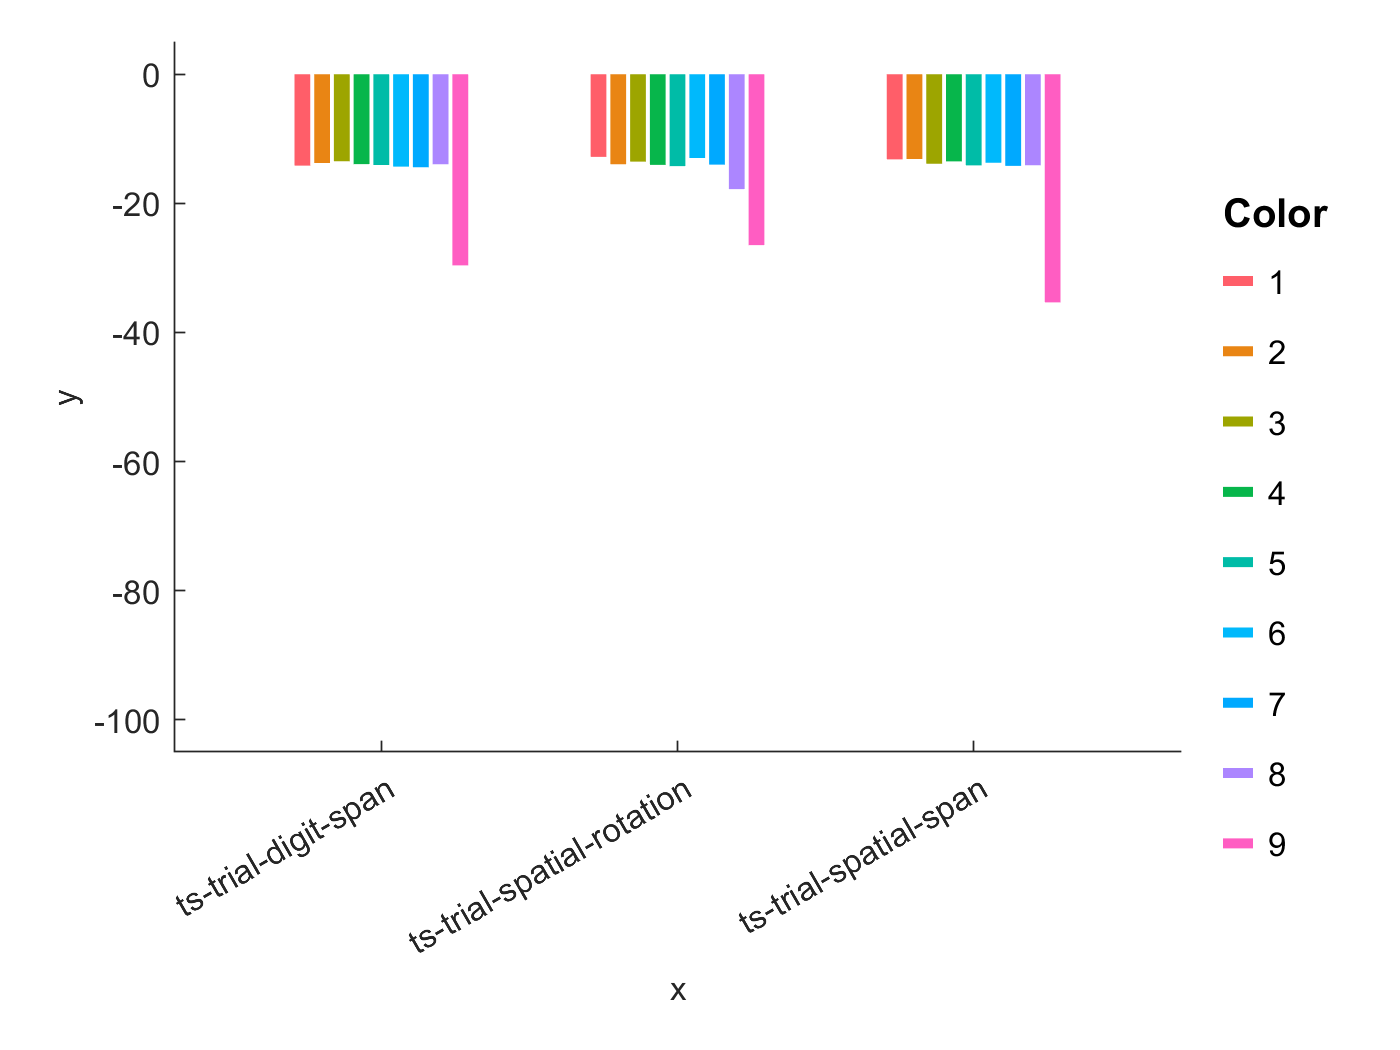


%Plotting omissions per type
dt=gramm('x',omissions.trial_task_type,'y',omissions.percent,'color',omissions.occurrence);
dt.stat_summary('geom',{'bar'});
figure
dt.draw();

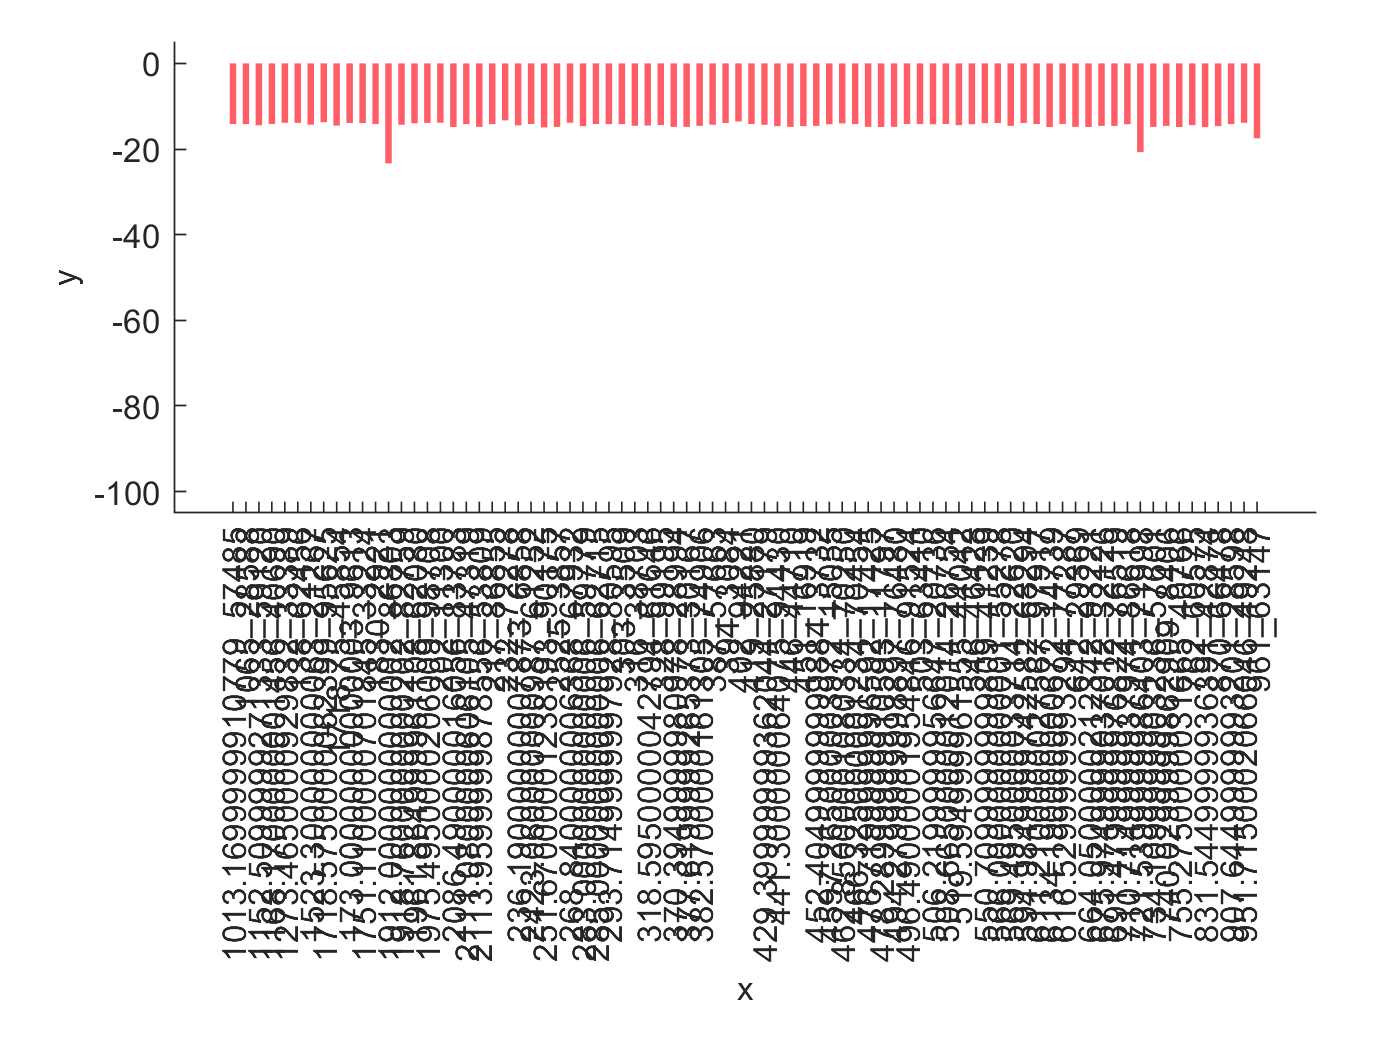

%Interesting- we don't usually have 9th or 10th occurrences, as seen above,
%and when we do they have a lot higher omissions. We'll see if that plays
%into occurrence or switch cost

%and overall
dt=gramm('x',omissions.auto_participant_id,'y',omissions.percent);
dt.stat_summary('geom',{'bar'});
figure
dt.draw();

% Ok, so there's 2 or 3 participants who really dropped the ball. They can
% likely be excluded

%Exclude participants with more than 20% omissions overall
omissions =  varfun(sumom,df,'GroupingVariables',{'auto_participant_id'},'InputVariables',{'Correct'});
omissions.percent = (omissions.Fun_Correct./omissions.GroupCount)*100 ;
IDs_delete = omissions.auto_participant_id(omissions.percent>20) ;

df(ismember(df.auto_participant_id,IDs_delete),:)=[];
N2 = height(groupcounts(df,{'auto_participant_id'}))

N2 = 80

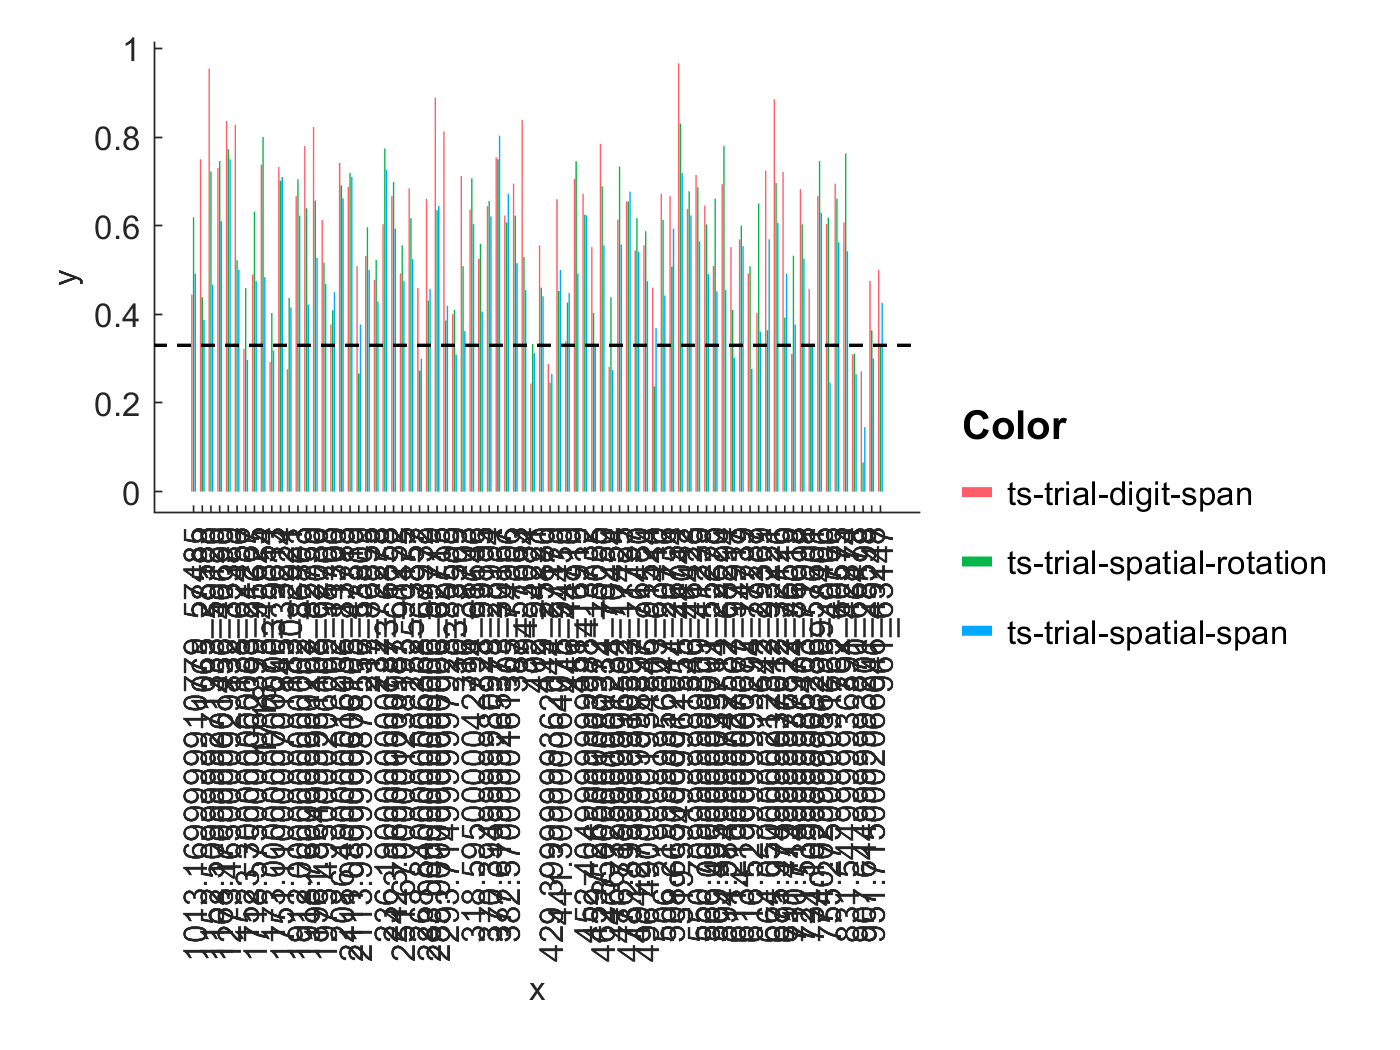

Less than 2 samples for CI computation...Skipping
Less than 2 samples for CI computation...Skipping
Less than 2 samples for CI computation...Skipping
Less than 2 samples for CI computation...Skipping
Less than 2 samples for CI computation...Skipping
Less than 2 samples for CI computation...Skipping
Less than 2 samples for CI computation...Skipping
Less than 2 samples for CI computation...Skipping
Less than 2 samples for CI computation...Skipping
Less than 2 samples for CI computation...Skipping
Less than 2 samples for CI computation...Skipping
Less than 2 samples for CI computation...Skipping
Less than 2 samples for CI computation...Skipping
Less than 2 samples for CI computation...Skipping
Less than 2 samples for CI computation...Skipping
Less than 2 samples for CI computation...Skipping
Less than 2 samples for CI computation...Skipping
Less than 2 samples for CI computation...Skipping
Less than 2 samples for CI computation...Skipping
Less than 2 samples for CI computation...Skipping


% Ok, so no one was deleted

%Looking at accuracy per trial type - chance level is 33% because there were 3 options
statarray = grpstats(df,{'auto_participant_id','trial_task_type'},'nansum','DataVars',{'Correct'});
statarray.mean_accuracy = statarray.nansum_Correct./statarray.GroupCount;

% Ploting accuracy per type
dt=gramm('x',statarray.auto_participant_id,'y',statarray.mean_accuracy,'color',statarray.trial_task_type);
dt.stat_summary('geom',{'bar'});
dt.geom_hline("yintercept",0.33,"style",'k--');
figure
dt.draw();


% This will check which participants have accuracy below chance
IDs_delete_extensive = statarray.auto_participant_id(statarray.mean_accuracy<0.33);

[ids,~,idx]=unique(IDs_delete_extensive);
n = accumarray(idx(:),1) ;
participants_alltasks_chance = ids(n==3);

% Table excluding participants with any taks at chance level
df_clean_ext = df;
df_clean_ext(ismember(df_clean_ext.auto_participant_id,IDs_delete_extensive),:)=[];
N_clean_ext = height(groupcounts(df_clean_ext,{'auto_participant_id'}))  % we now have 61 participants

N_clean_ext = 61

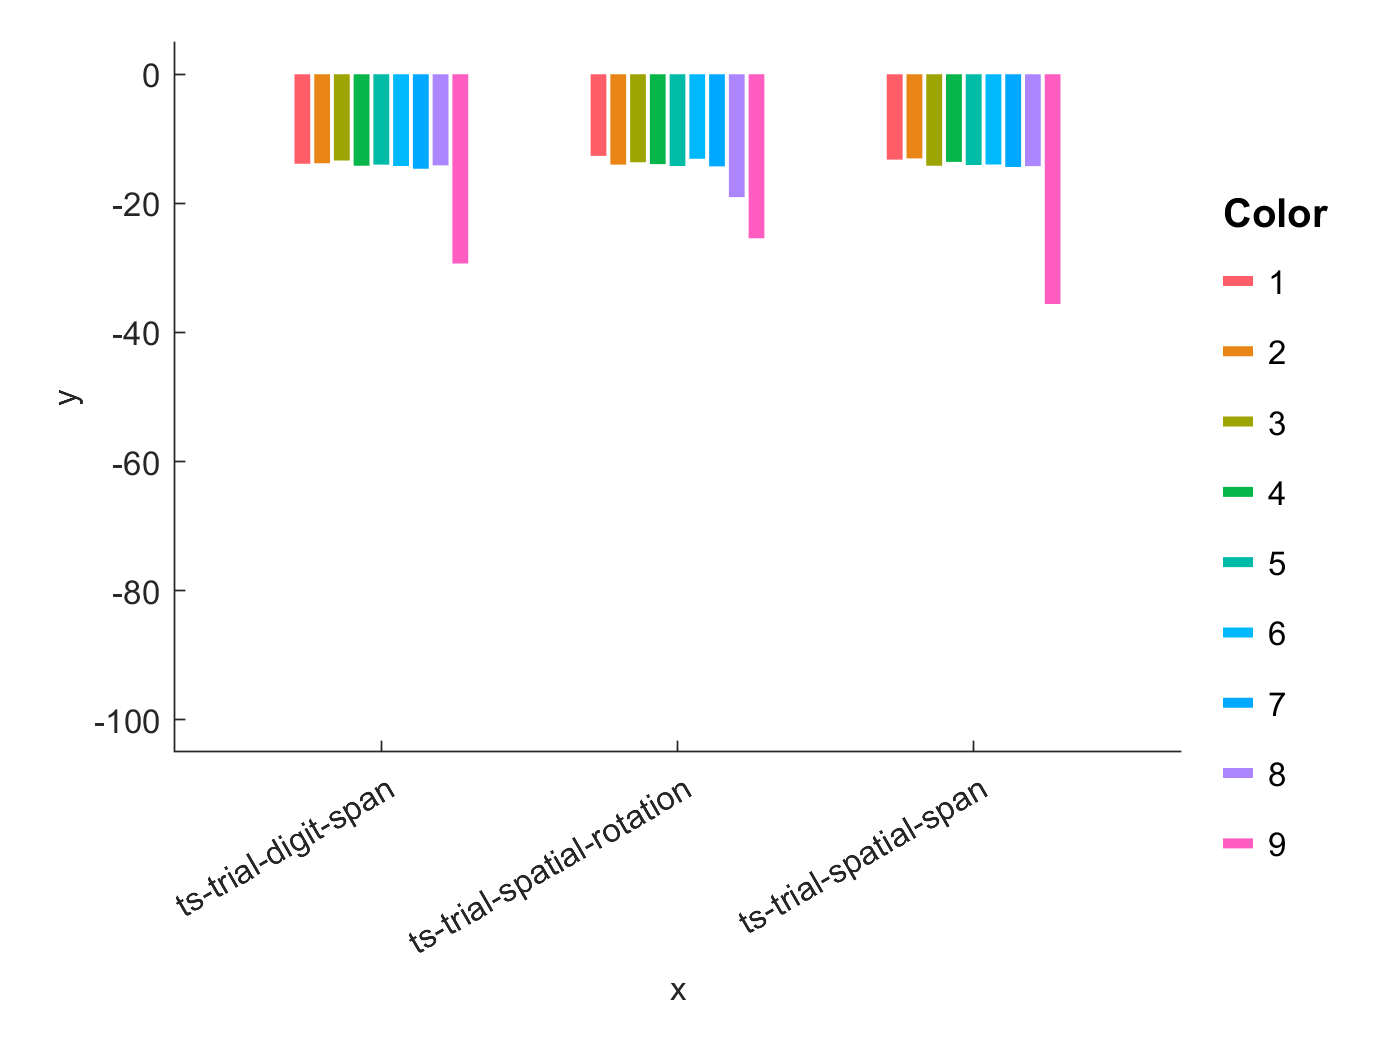



% Ploting omissions per type after removing the participants who had many
% omissions
sumom2 = @(x) sum(-1);
omissions2 =  varfun(sumom2,df_clean_ext,'GroupingVariables',{'auto_participant_id','trial_task_type', 'occurrence'},'InputVariables',{'Correct'});
omissions2.percent = (omissions2.Fun_Correct./omissions2.GroupCount)*100 ;

dt=gramm('x',omissions2.trial_task_type,'y',omissions2.percent,'color',omissions2.occurrence);
dt.stat_summary('geom',{'bar'});
figure
dt.draw();

% Still the same pattern, which makes me think the further the task goes on,
% the worse people perform (ie, occurrence effect in accuracy)

**4. Demographics**

% demographics = groupsummary(df,{'participant_age','participant_gender','auto_participant_id'})
% demographics.participant_age = str2double(demographics.participant_age)
% 
% % Age
% mean(demographics.participant_age)
% min(demographics.participant_age)
% max(demographics.participant_age)

% Gender
Gender = df_clean_ext.participant_gender;
Sex = {};
for ii = 1:length(Gender)
    if strcmpi(Gender{ii},'Female')
        Sex{ii} = 'female';
    elseif strcmpi(Gender{ii},'Female ')
        Sex{ii} = 'female';
    elseif strcmpi(Gender{ii},'Male')
        Sex{ii} = 'male';
    else
        Sex{ii} = Gender{ii};
    end
end

df_clean_ext.Gender = Sex'; 
groupcounts(groupcounts(df_clean_ext,{'Gender','auto_participant_id'}),'Gender')

ans = 3×3 table
      Gender      GroupCount    Percent
    __________    __________    _______

    {'F'     }         1        1.6393 
    {'female'}        51        83.607 
    {'male'  }         9        14.754 


**5.1 Accuracy basic stats**

statarray_df_clean_ext = grpstats(df_clean_ext,{'auto_participant_id','trial_task_type', 'occurrence'},'nansum','DataVars',{'Correct'});
statarray_df_clean_ext.mean_accuracy = statarray_df_clean_ext.nansum_Correct./statarray_df_clean_ext.GroupCount;

% Testing normalicy of overall accuracy 
[h,p,ksstat,cv] = kstest(statarray_df_clean_ext.mean_accuracy)

h = logical
   1


p = 0

ksstat = 0.5483

cv = 0.0348

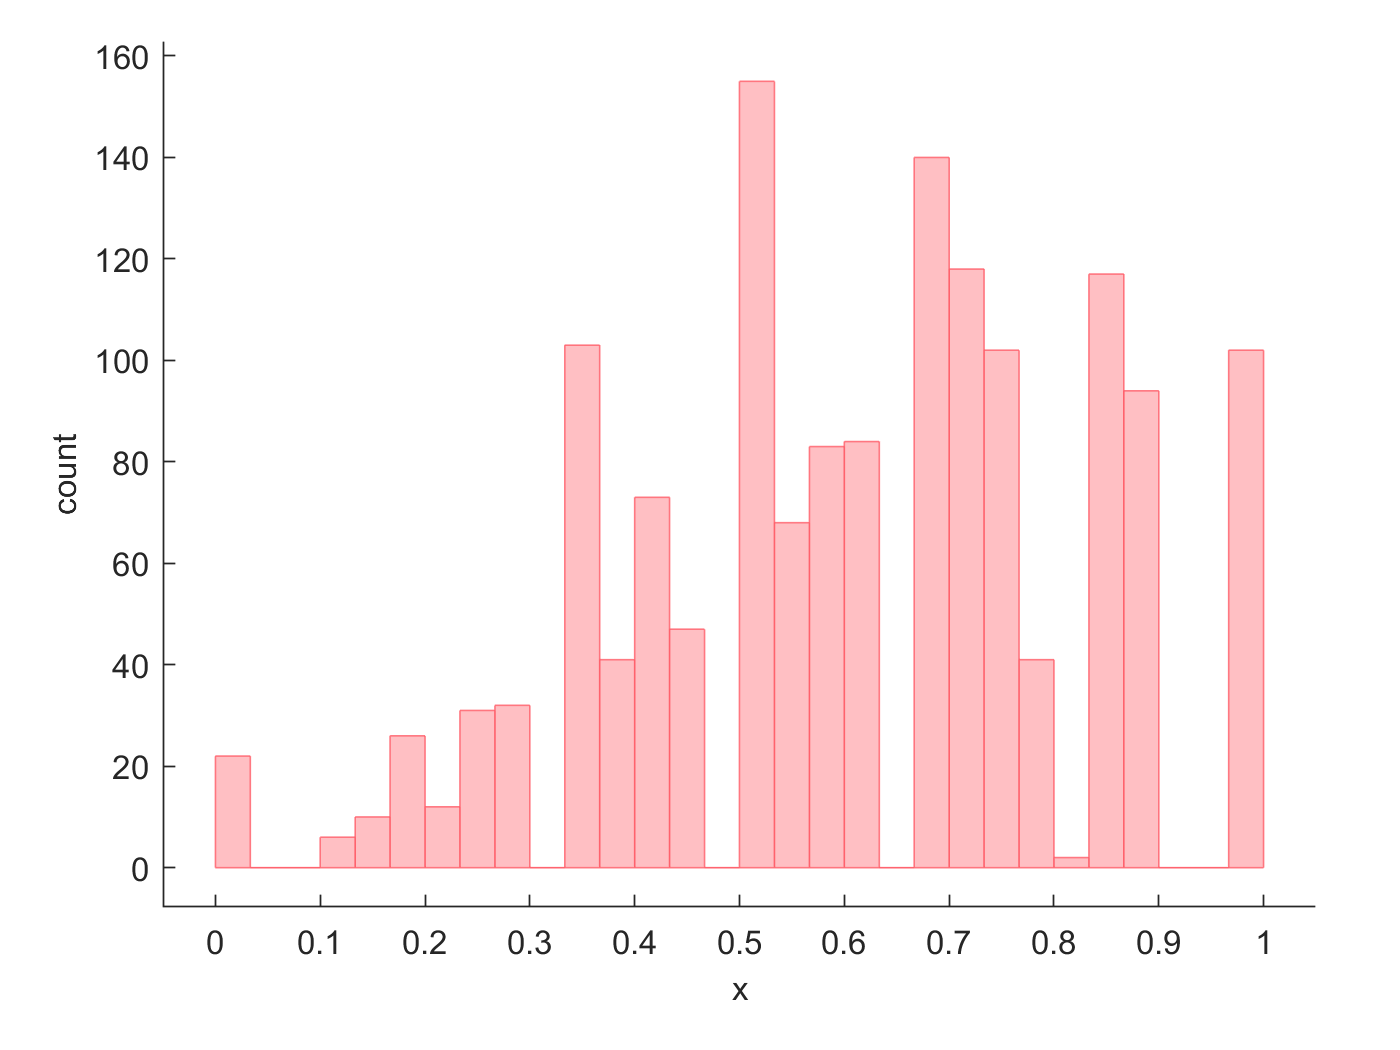

% It's barreeelllyyy not normal, and though normalization reduces variance,
% but I'm not sure that will wipe out meaningful effects. I'll look at some plots
% later on to help decide. 

dt=gramm('x',statarray_df_clean_ext.mean_accuracy);
dt.stat_bin('geom','overlaid_bar');
figure
dt.draw();


%By Pilot Type
[grpSTD,grpMean,grpName] = grpstats(statarray_df_clean_ext.mean_accuracy,statarray_df_clean_ext.trial_task_type,{'std','mean','gname'})

grpSTD =     0.2299
    0.2116
    0.2121


grpMean =     0.6631
    0.5368
    0.6151


grpName = 3×1 cell array
    {'ts-trial-digit-span'      }
    {'ts-trial-spatial-span'    }
    {'ts-trial-spatial-rotation'}


**5.2  Accuracy per Task Type**

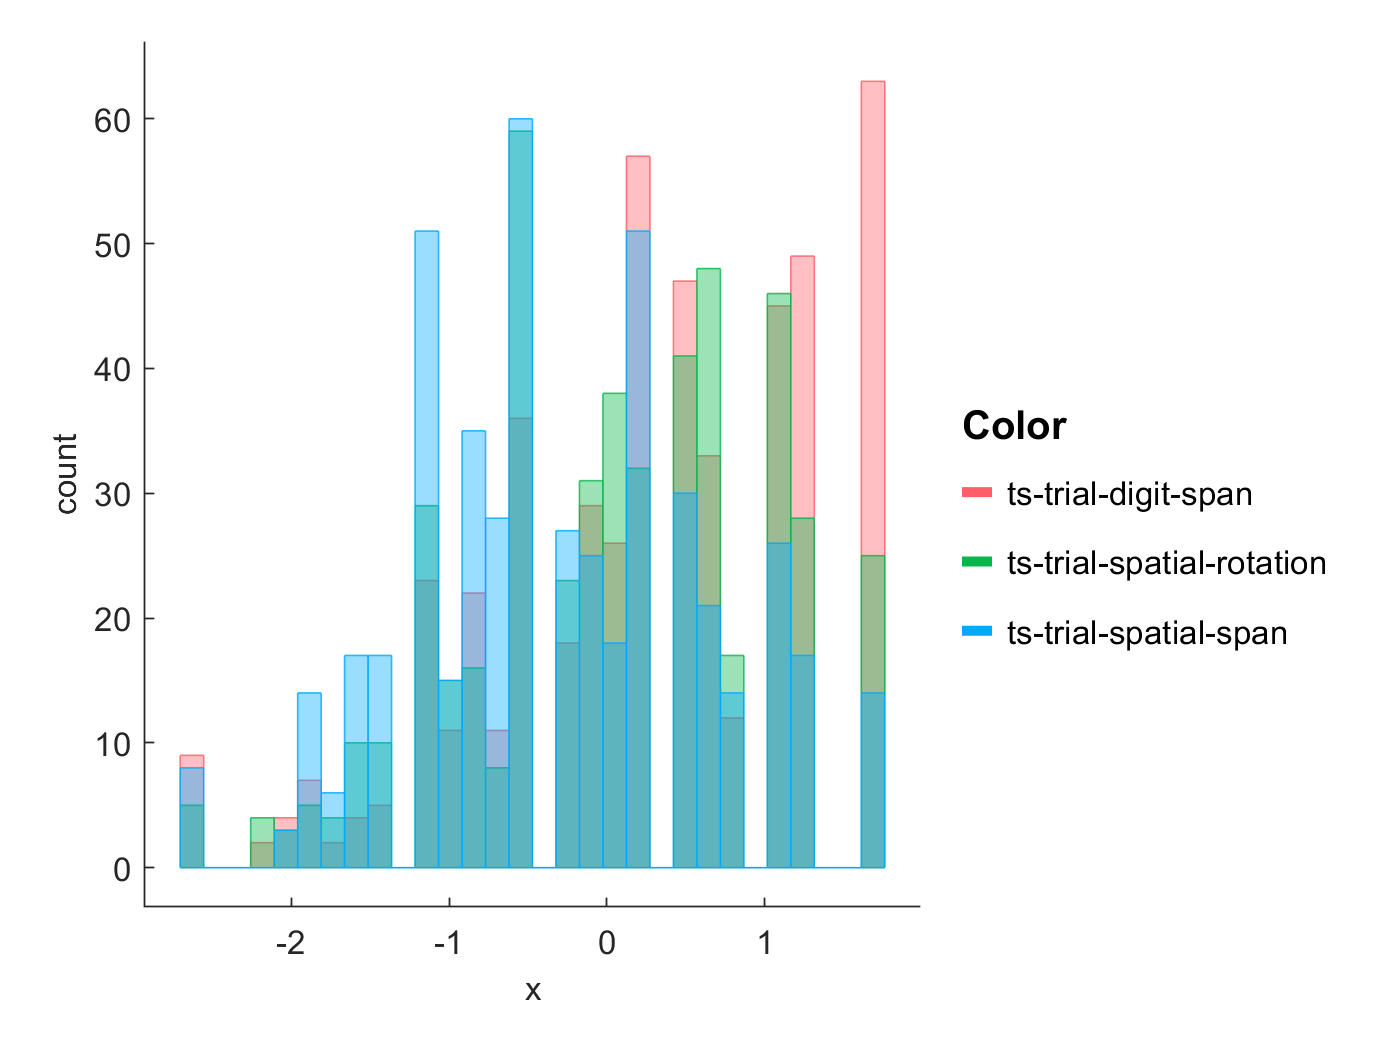

% Compute and normalize mean accuracy data 
% statarray = grpstats(df_clean_ext,{'auto_participant_id','trial_task_type','occurrence'},'nansum','DataVars',{'Correct'});
% statarray.mean_accuracy = statarray_df_clean_ext.nansum_Correct./statarray_df_clean_ext.GroupCount;

statarray = grpstats(df_clean_ext,{'auto_participant_id','trial_task_type','occurrence'},'nansum','DataVars',{'Correct'});
statarray.mean_accuracy = statarray.nansum_Correct./statarray.GroupCount;
statarray.mean_accuracy = normalize(statarray.mean_accuracy);

dt=gramm('x',statarray.mean_accuracy,"color",statarray.trial_task_type);
dt.stat_bin('geom','overlaid_bar'); 
figure()
dt.draw();


%Summary of Overall Accuracy Stats
columns = statarray_df_clean_ext(:,{'mean_accuracy'});
AccStats = grpstats(columns,[],{'mean','std','median'})

AccStats = 1×4 table
           GroupCount    mean_mean_accuracy    std_mean_accuracy    median_mean_accuracy
           __________    __________________    _________________    ____________________

    All       1509            0.60569               0.22418                0.625        



%By Pilot Type
[grpSTD,grpMean,grpName] = grpstats(statarray_df_clean_ext.mean_accuracy,statarray_df_clean_ext.trial_task_type,{'std','mean','gname'})

grpSTD =     0.2299
    0.2116
    0.2121


grpMean =     0.6631
    0.5368
    0.6151


grpName = 3×1 cell array
    {'ts-trial-digit-span'      }
    {'ts-trial-spatial-span'    }
    {'ts-trial-spatial-rotation'}



%Test for differences in accuracy per occurrence per task type.
lme = fitglme(statarray,'mean_accuracy ~ trial_task_type*occurrence + (1|auto_participant_id)');
anova(lme)

ans =     ANOVA marginal tests: DFMethod = 'residual'

    Term                                  FStat       DF1    DF2     pValue    
    {'(Intercept)'               }          14.976    1      1503    0.00011354
    {'trial_task_type'           }          10.829    2      1503    2.1414e-05
    {'occurrence'                }          2.6428    1      1503       0.10423
    {'trial_task_type:occurrence'}        0.059914    2      1503       0.94185


lme

lme = Generalized linear mixed-effects model fit by PL

Model information:
    Number of observations            1509
    Fixed effects coefficients           6
    Random effects coefficients         61
    Covariance parameters                2
    Distribution                    Normal
    Link                            Identity
    FitMethod                       MPL   

Formula:
    mean_accuracy ~ 1 + trial_task_type*occurrence + (1 | auto_participant_id)

Model fit statistics:
    AIC       BIC     LogLikelihood    Deviance
    4076.4    4119    -2030.2          4060.4  

Fixed effects coefficients (95% CIs):
    Name                                                            Estimate       SE          tStat         DF      pValue        Lower        Upper    
    {'(Intercept)'                                         }            0.38033     0.09828        3.8699    1503    0.00011354      0.1

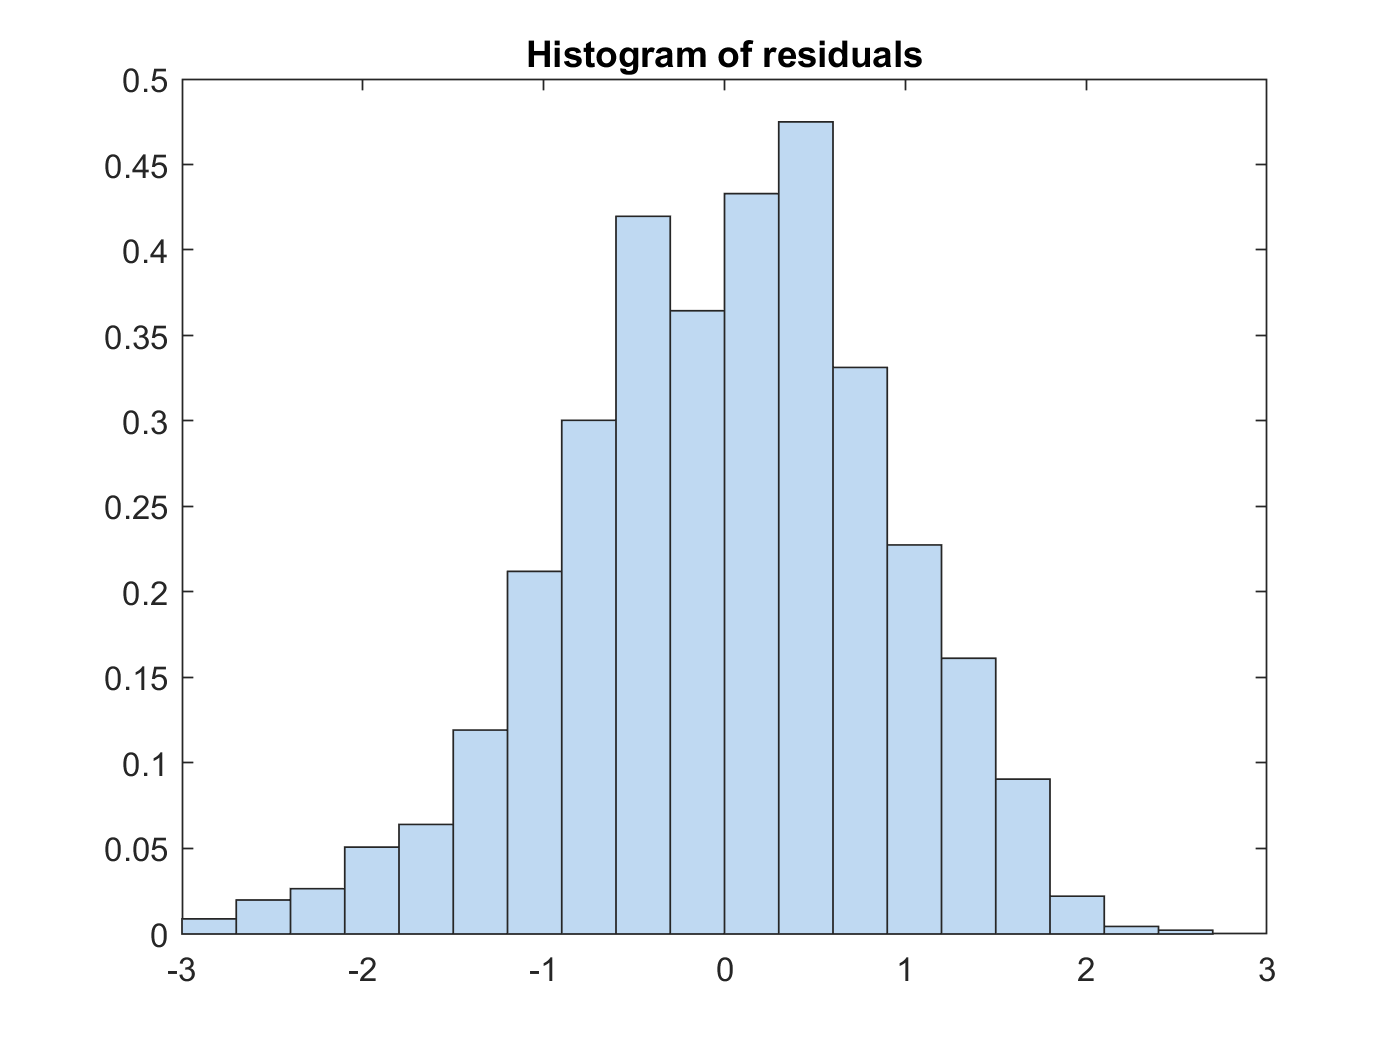

figure()
plotResiduals(lme,'histogram')

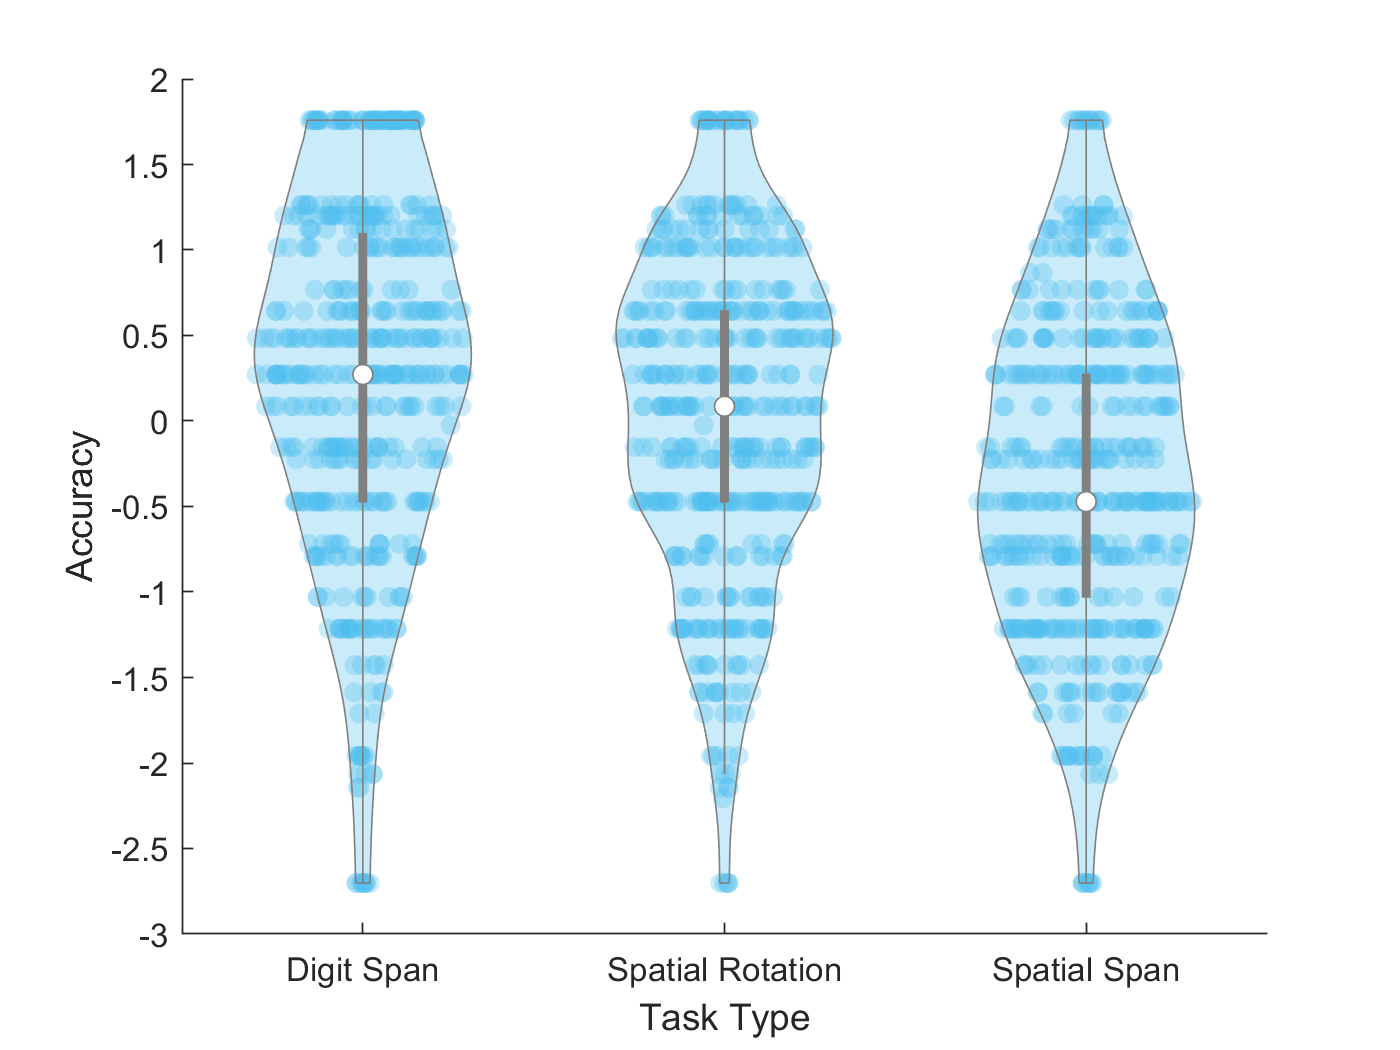

%There is a significant effect of task type on accuracy

tasklabels=['Digit Span      ';'Spatial Rotation';'Spatial Span    '];

figure()
vs = violinplot(statarray.mean_accuracy,statarray.trial_task_type,'ViolinColor',[0.301, 0.745, 0.933]);
ylabel('Accuracy');
xlabel('Task Type')
xticklabels(tasklabels);

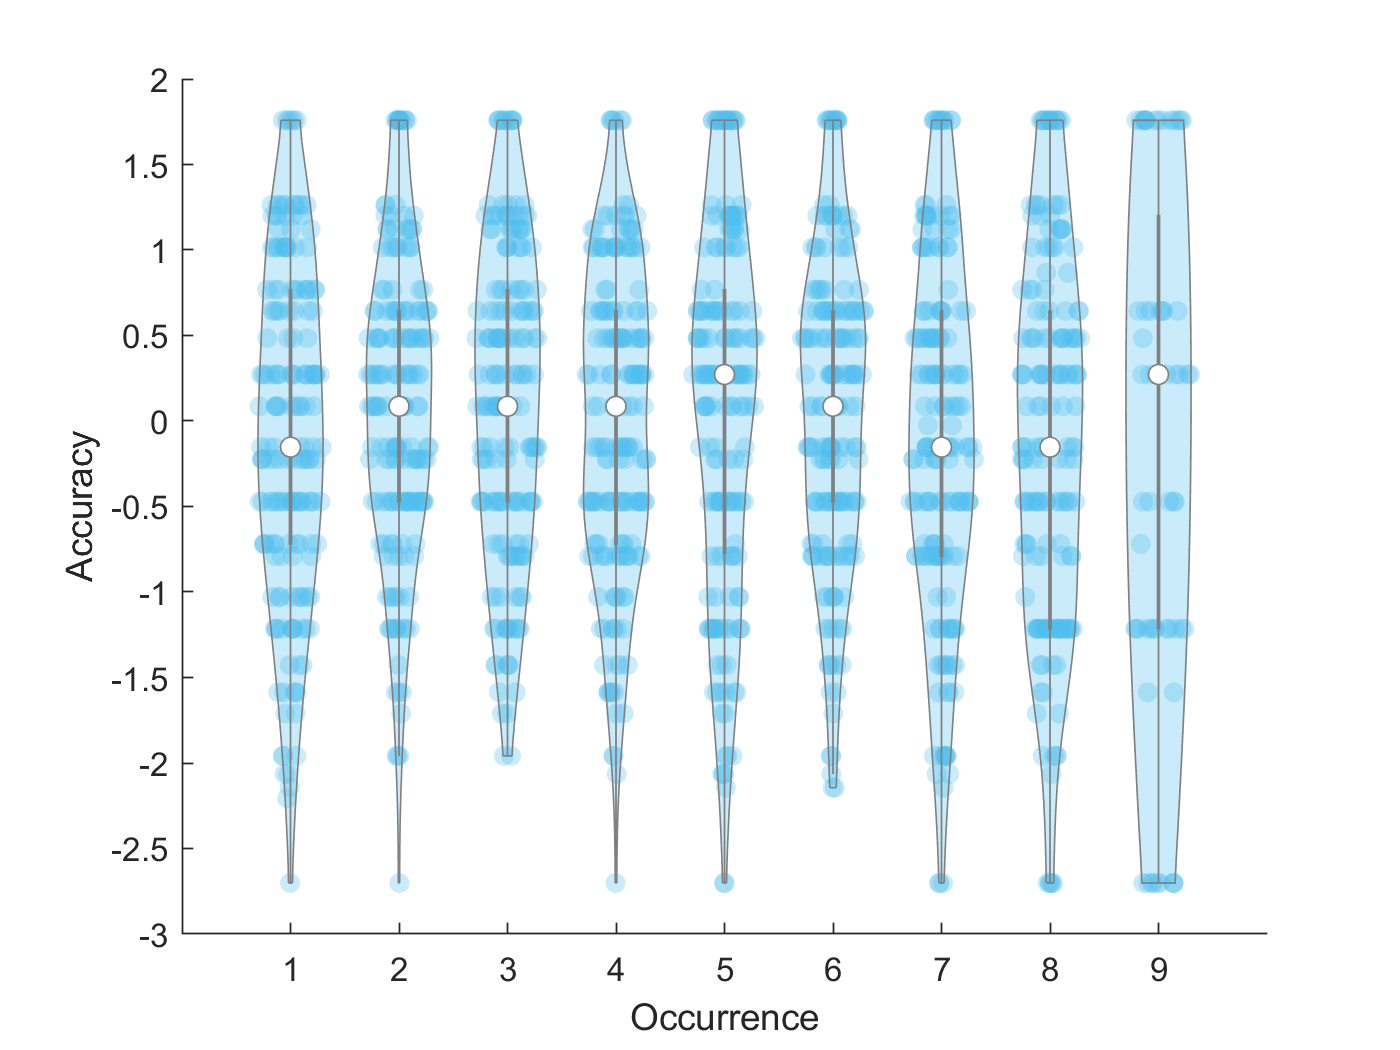



figure()
vs = violinplot(statarray.mean_accuracy,statarray.occurrence,'ViolinColor',[0.301, 0.745, 0.933]);
ylabel('Accuracy');
xlabel('Occurrence')



% Running TTests to show sig diffs
statarray = grpstats(df_clean_ext,{'trial_task_type','auto_participant_id','occurrence'},'nansum','DataVars',{'Correct'});
statarray.mean_accuracy = statarray.nansum_Correct./statarray.GroupCount;
statarray.mean_accuracy = normalize(statarray.mean_accuracy);
divide=height(statarray)/3

divide = 503


DS=statarray.mean_accuracy(1:divide);
SR=statarray.mean_accuracy(divide+1:divide*2);
SS=statarray.mean_accuracy((divide*2)+1:divide*3);

% SS vs SR
[H,P,CHI,STATS]=ttest(SS,SR)

H = 1

P = 6.3980e-09

CHI =     0.2216
    0.4424


STATS = struct with fields:
    tstat: 5.9079
       df: 502
       sd: 1.2605


% SR has sig higher accuracy than SS (t(502)=-6.1, p=5.5e-11)

% SS vs DS
[H,P,CHI,STATS]=ttest(SS,DS)

H = 1

P = 1.3275e-04

CHI =    -0.3585
   -0.1163


STATS = struct with fields:
    tstat: -3.8512
       df: 502
       sd: 1.3823


% DS has significantly higher accuracy than the SS (t(502)=-9.6, p=3.1e-20)

% SR vs DS
[H,P,CHI,STATS]=ttest(SR,DS)

H = 1

P = 6.5987e-19

CHI =    -0.6904
   -0.4484


STATS = struct with fields:
    tstat: -9.2470
       df: 502
       sd: 1.3810


% DS has significantly higher accuracy than the SR (t(502)=-3.6, p=3.7e-04)


**6  Reaction time (RT)**

**6.1 RT basic stats**

% This changes all negative response times (all which are missed trials) to nan
% df_clean_ext.response_time(df_clean_ext.response_time < 0) = nan;

% First create a variable for RT correct and another for RT incorrect. I
% use only correct responses in the analysis
RT_Correct = [];
RT_Incorrect = [];
for ii=1:length(df_clean_ext.Correct)
    if (df_clean_ext.Correct(ii)==1)
        RT_Correct(ii) = df_clean_ext.response_time(ii);
        RT_Incorrect(ii) = NaN;
    else
        RT_Correct(ii) = NaN;
        RT_Incorrect(ii) = df_clean_ext.response_time(ii);
    end
end

df_clean_ext.RT_Correct = RT_Correct';

% Checking normalcy of RT
[h,p,ksstat,cv] = kstest(df_clean_ext.RT_Correct)

h = logical
   1


p = 0

ksstat = 1

cv = 0.0167

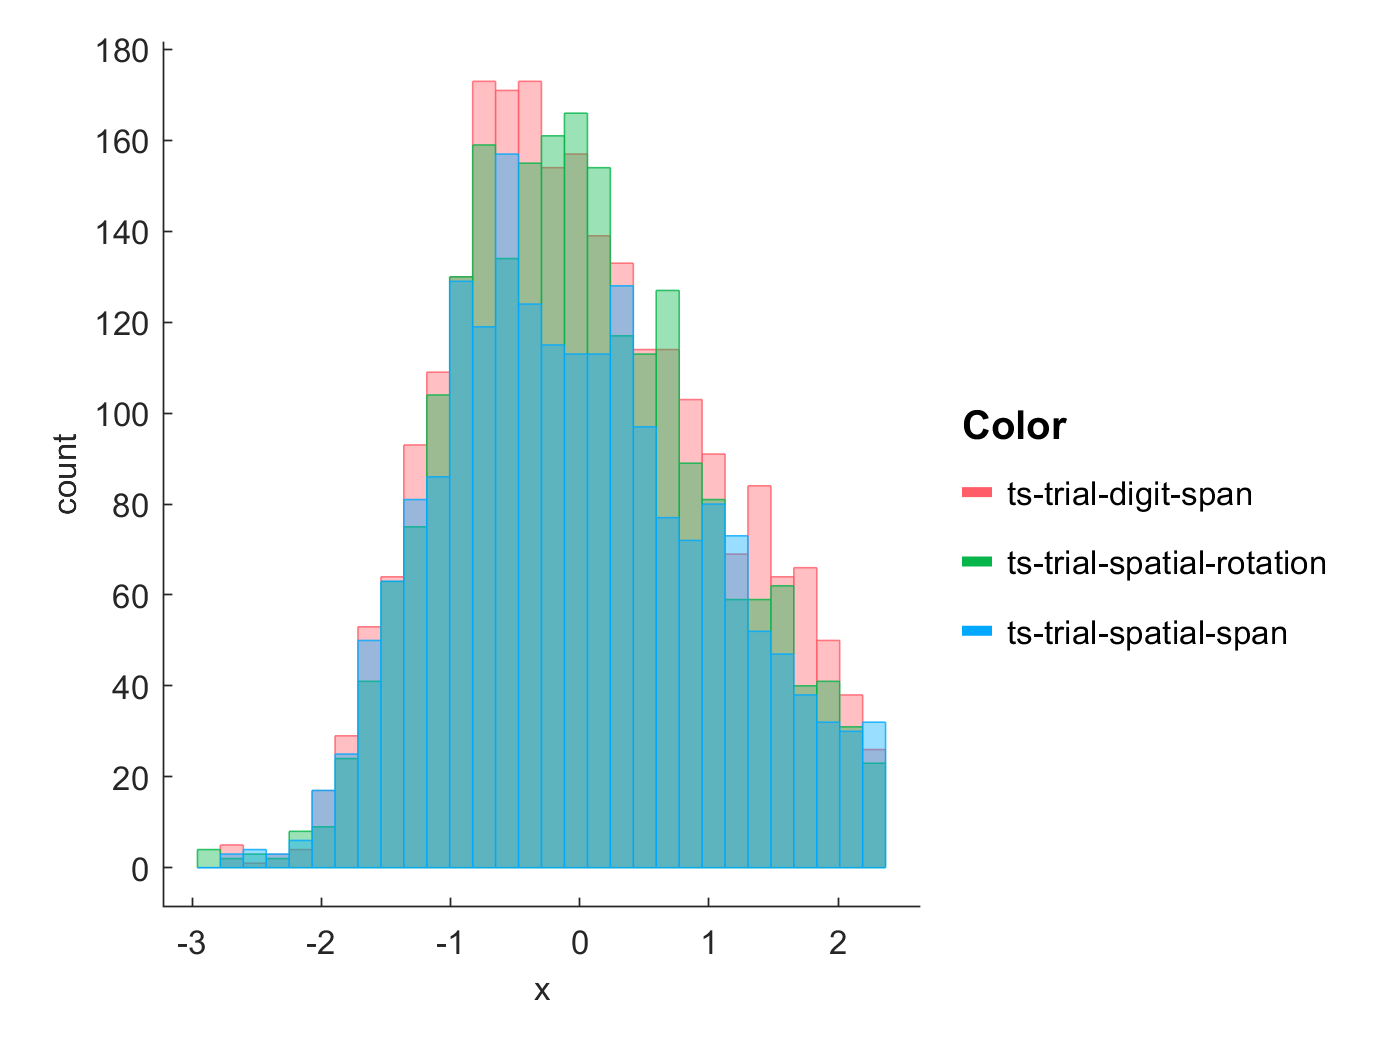

% Fails test of normalcy; I'll normalize it

df_clean_ext.RT_Correct = normalize(df_clean_ext.RT_Correct);

dt=gramm('x',df_clean_ext.RT_Correct,'color', df_clean_ext.trial_task_type);
dt.stat_bin('geom','overlaid_bar');
figure
dt.draw();


%Summary of Overall MRT Stats
columns = df_clean_ext(:,{'RT_Correct'});
RTStats = grpstats(columns,[],{'mean','std','median'})

RTStats = 1×4 table
           GroupCount    mean_RT_Correct    std_RT_Correct    median_RT_Correct
           __________    _______________    ______________    _________________

    All      10909         -1.4123e-15            1               -0.084217    


%By Pilot Type
[grpSTD,grpMean,grpName] = grpstats(df_clean_ext.RT_Correct,df_clean_ext.trial_task_type,{'std','mean','gname'})

grpSTD =     1.0070
    1.0193
    0.9748


grpMean =     0.0222
   -0.0268
   -0.0006


grpName = 3×1 cell array
    {'ts-trial-digit-span'      }
    {'ts-trial-spatial-span'    }
    {'ts-trial-spatial-rotation'}


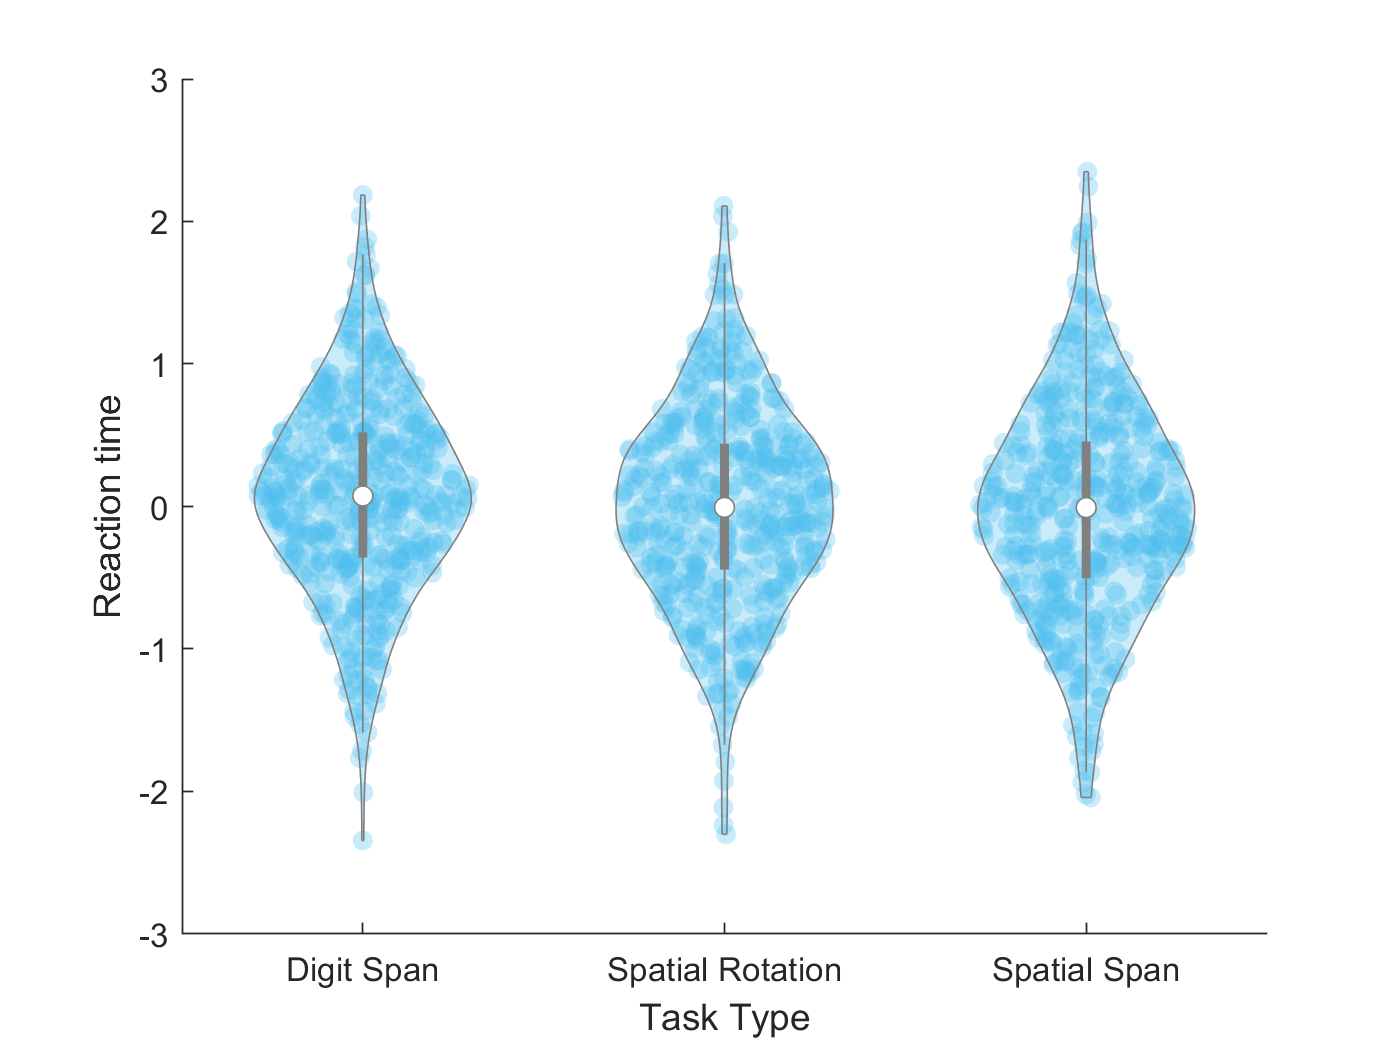


% Plotting RT per pilot version per type
statarray_df_clean_ext = grpstats(df_clean_ext,{'auto_participant_id','trial_task_type', 'occurrence'},'nanmean','DataVars',{'RT_Correct'});


figure()
vs = violinplot(statarray_df_clean_ext.nanmean_RT_Correct,statarray_df_clean_ext.trial_task_type,'ViolinColor',[0.301, 0.745, 0.933]);
ylabel('Reaction time');
xlabel('Task Type')
ylim([-3 3])
xticklabels(tasklabels)

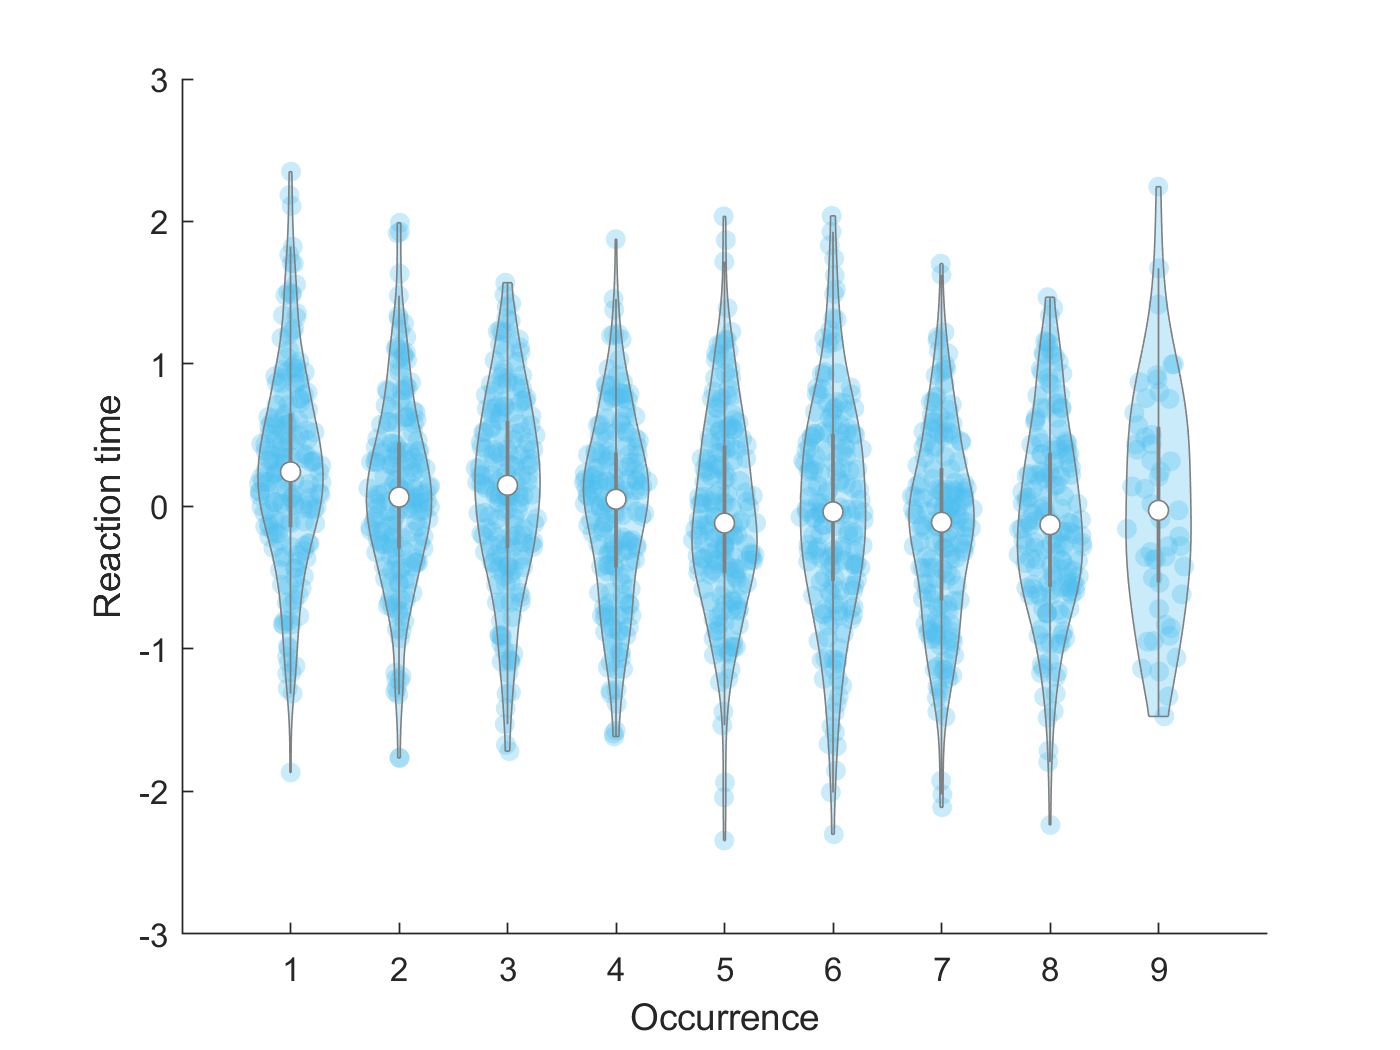


figure()
vs = violinplot(statarray_df_clean_ext.nanmean_RT_Correct,statarray_df_clean_ext.occurrence,'ViolinColor',[0.301, 0.745, 0.933]);
ylabel('Reaction time');
ylim([-3 3])
xlabel('Occurrence')


%Testing for effect of task type and occurrence
lme_light_clean = fitglme(statarray_df_clean_ext,'nanmean_RT_Correct ~ trial_task_type*occurrence + (1|auto_participant_id)');
anova(lme_light_clean)

ans =     ANOVA marginal tests: DFMethod = 'residual'

    Term                                  FStat       DF1    DF2     pValue   
    {'(Intercept)'               }          8.8998    1      1481    0.0028986
    {'trial_task_type'           }        0.086405    2      1481      0.91723
    {'occurrence'                }          8.3854    1      1481    0.0038379
    {'trial_task_type:occurrence'}          1.4302    2      1481      0.23958


lme_light_clean

lme_light_clean = Generalized linear mixed-effects model fit by PL

Model information:
    Number of observations            1487
    Fixed effects coefficients           6
    Random effects coefficients         61
    Covariance parameters                2
    Distribution                    Normal
    Link                            Identity
    FitMethod                       MPL   

Formula:
    nanmean_RT_Correct ~ 1 + trial_task_type*occurrence + (1 | auto_participant_id)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    2781.1    2823.6    -1382.6          2765.1  

Fixed effects coefficients (95% CIs):
    Name                                                            Estimate     SE          tStat       DF      pValue       Lower        Upper    
    {'(Intercept)'                                         }          0.22322    0.074825      2.9833    1481    0.00289

% There's an effect of occurrence on RT

%By Pilot Type
[grpMean,grpName] = grpstats(df_clean_ext.RT_Correct,df_clean_ext.occurrence,{'mean','gname'})

grpMean =     0.2023
    0.0668
    0.0664
   -0.0078
   -0.0779
   -0.0517
   -0.1433
   -0.0793
   -0.0461


grpName = 9×1 cell array
    {'1'}
    {'2'}
    {'3'}
    {'4'}
    {'5'}
    {'6'}
    {'7'}
    {'8'}
    {'9'}


% total range- 5.3 

% biggest diff- occ 1 and 7- 0.34- 6%

**7. Switch cost**

**7.1 Switch cost in accuracy - overall and per task type**

% Creating new variable for switches (in the column as "Switch") - 1 = switch , 0 = stay
switchtypename = 'ts-trial-';
Switch = [];
for ii=1:length(df_clean_ext.switchtype)
    if strncmp(df_clean_ext.switchtype(ii), switchtypename, 2)
        Switch(ii)=1;
    else
        Switch(ii)=0;
    end
end

df_clean_ext.Switch = Switch';

% Looking just at Switch vs non-Switch
statarray_df_clean_ext = grpstats(df_clean_ext,{'Switch', 'auto_participant_id','trial_task_type','occurrence'},'nansum','DataVars',{'Correct'});
statarray_df_clean_ext.mean_accuracy = statarray_df_clean_ext.nansum_Correct./statarray_df_clean_ext.GroupCount;
statarray_df_clean_ext.mean_accuracy = normalize(statarray_df_clean_ext.mean_accuracy);
% Making sure they're the same length- there are more switch than stay
% trials
Switch=statarray_df_clean_ext.mean_accuracy(1:1505-57);
Stay=statarray_df_clean_ext.mean_accuracy(1506:2953);

[H,P,CI,STATS] = ttest(Switch,Stay)

H = 1

P = 0.0027

CI =     0.0380
    0.1809


STATS = struct with fields:
    tstat: 3.0036
       df: 1447
       sd: 1.3861


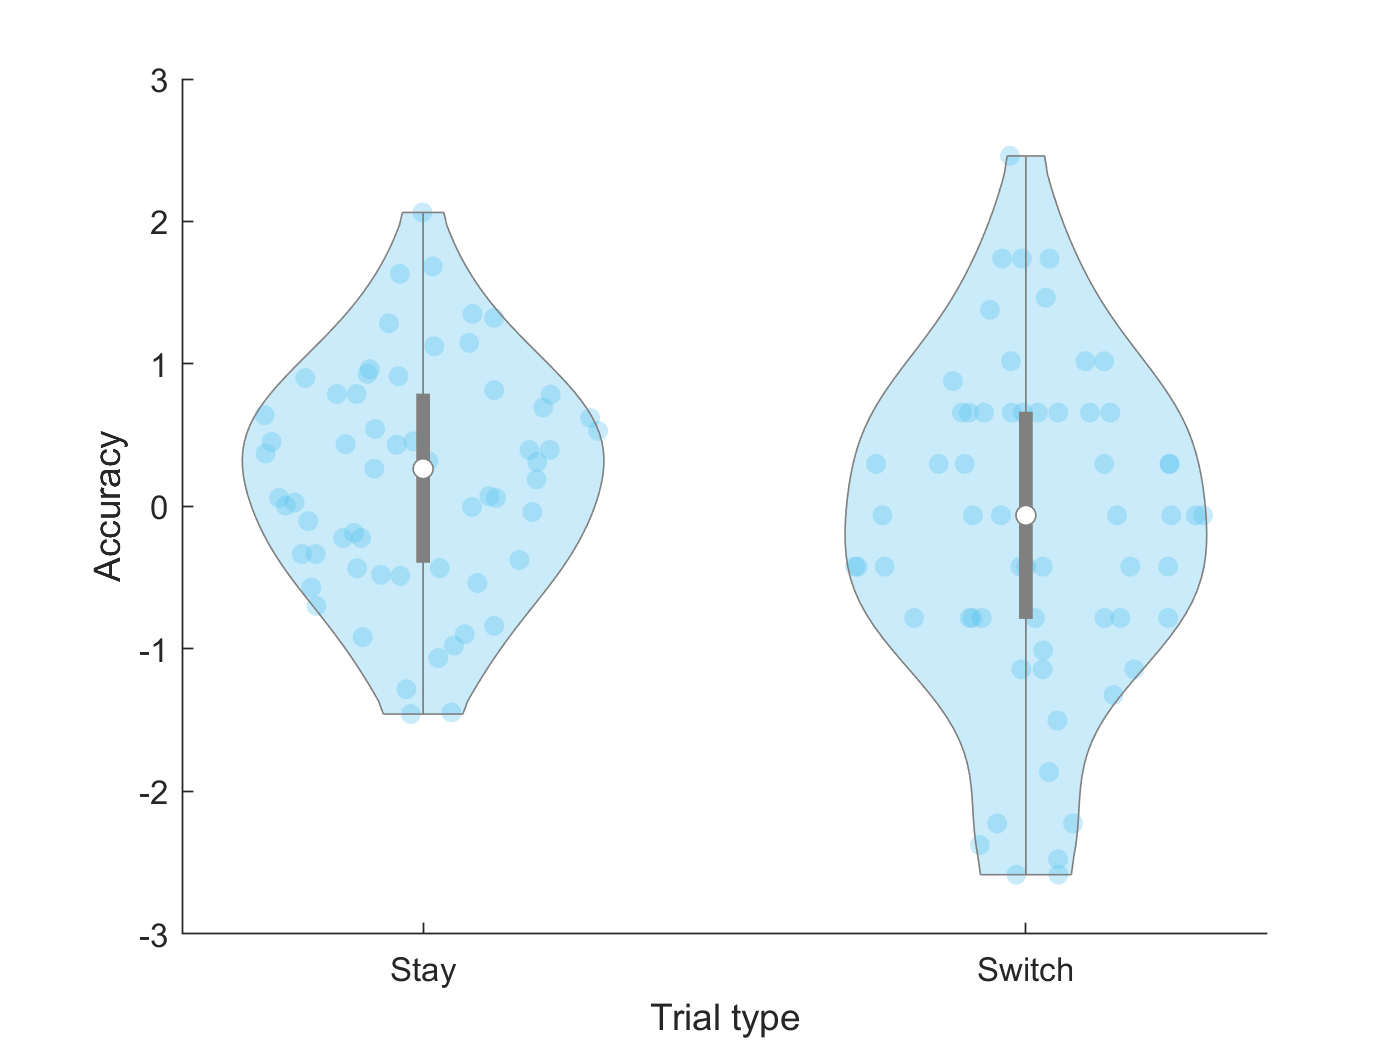

% There's a sig diff between between switch and non switch acc

% Organizing it this way helps plotting
statarray = grpstats(df_clean_ext,{'auto_participant_id','Switch'},'nansum','DataVars',{'Correct'});
statarray.mean_accuracy = statarray.nansum_Correct./statarray.GroupCount;
statarray.mean_accuracy = normalize(statarray.mean_accuracy);

figure()
vs = violinplot(statarray.mean_accuracy,statarray.Switch,'ViolinColor',[0.301, 0.745, 0.933]);
ylabel('Accuracy');
xlabel('Trial type')
xticklabels(['Stay  ';'Switch'])

ans = 'Runing stats for task ts-trial-digit-span'

ans =     ANOVA marginal tests: DFMethod = 'residual'

    Term                   FStat      DF1    DF2    pValue 
    {'(Intercept)'}        0.07928    1      120    0.77876
    {'Switch'     }        0.25213    1      120     0.6165


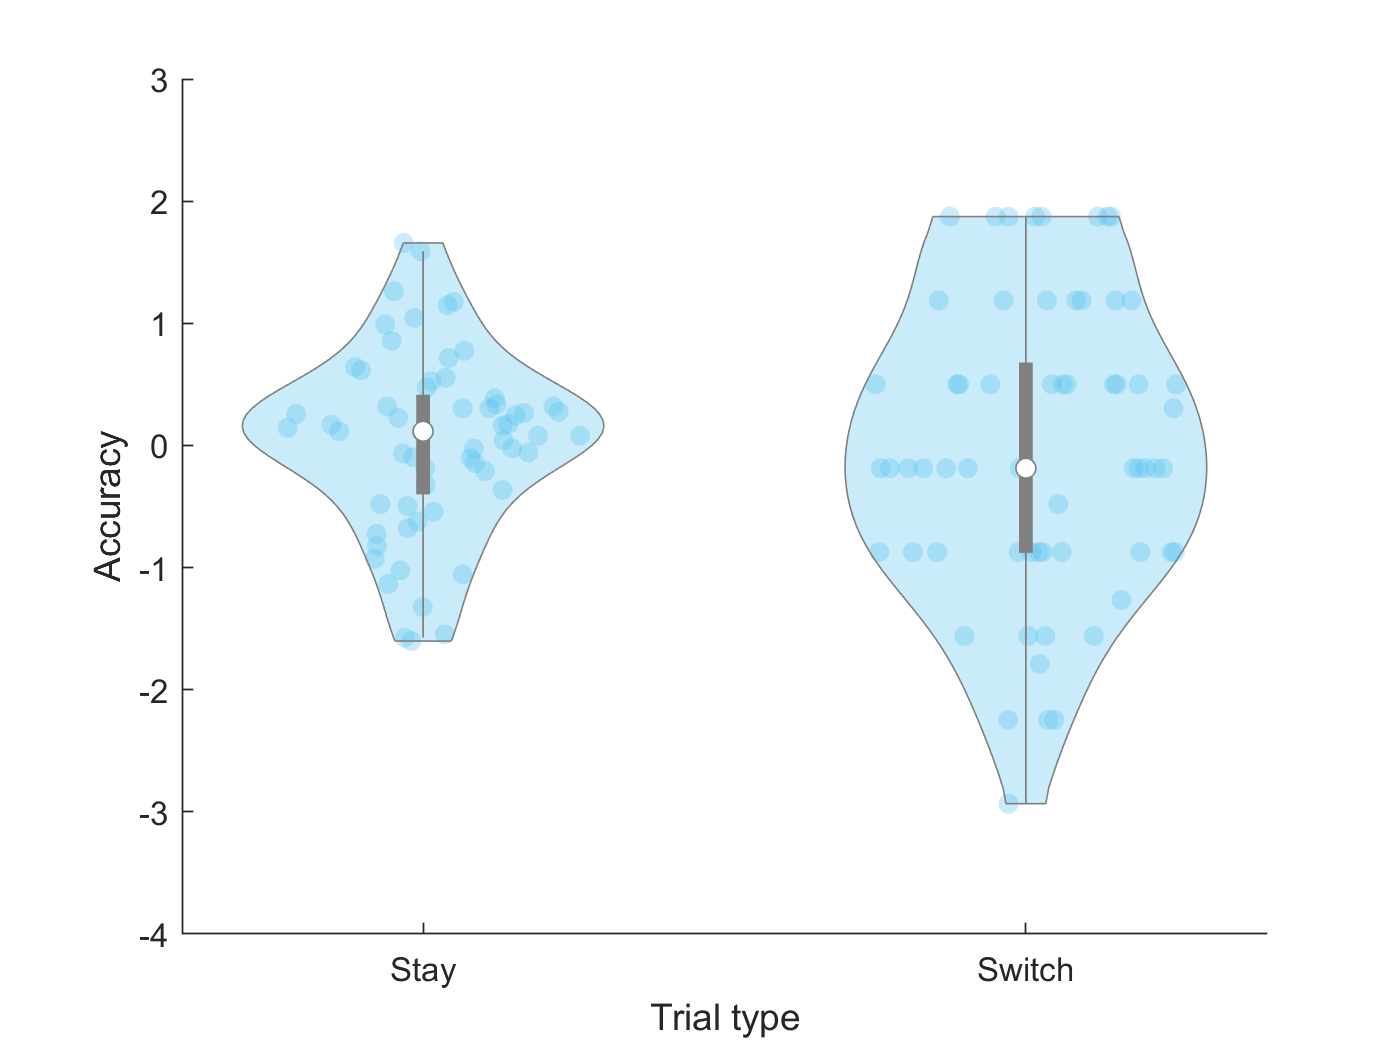

ans = 'Runing stats for task ts-trial-spatial-rotation'

ans =     ANOVA marginal tests: DFMethod = 'residual'

    Term                   FStat     DF1    DF2    pValue   
    {'(Intercept)'}        1.8637    1      120      0.17476
    {'Switch'     }        7.4053    1      120    0.0074712


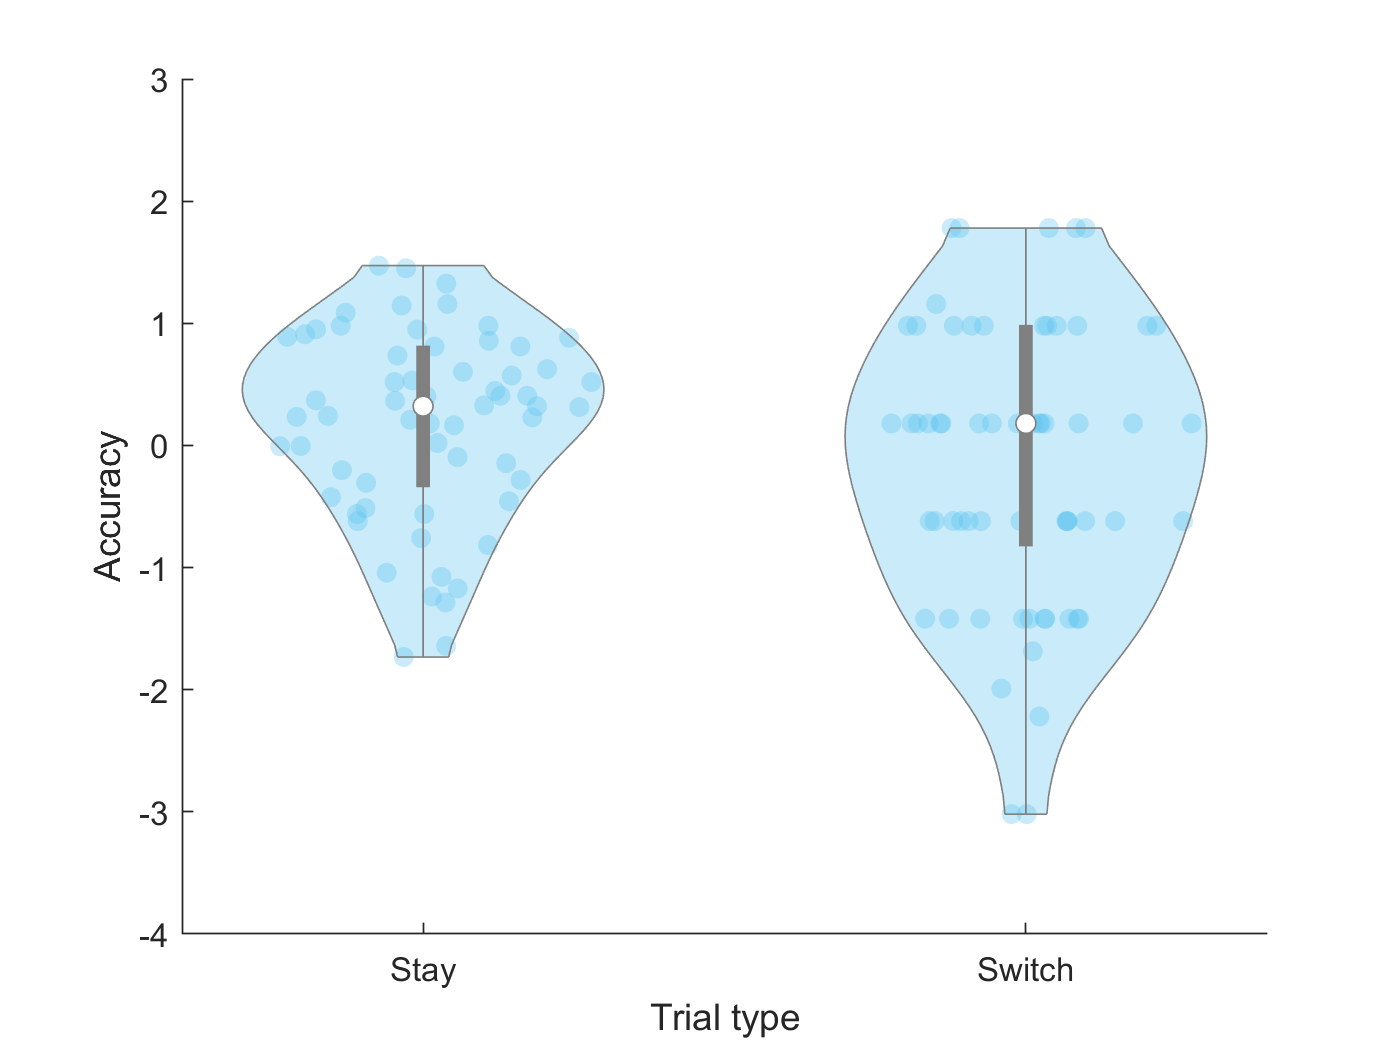

ans = 'Runing stats for task ts-trial-spatial-span'

ans =     ANOVA marginal tests: DFMethod = 'residual'

    Term                   FStat     DF1    DF2    pValue  
    {'(Intercept)'}         2.582    1      120     0.11071
    {'Switch'     }        7.3943    1      120    0.007514


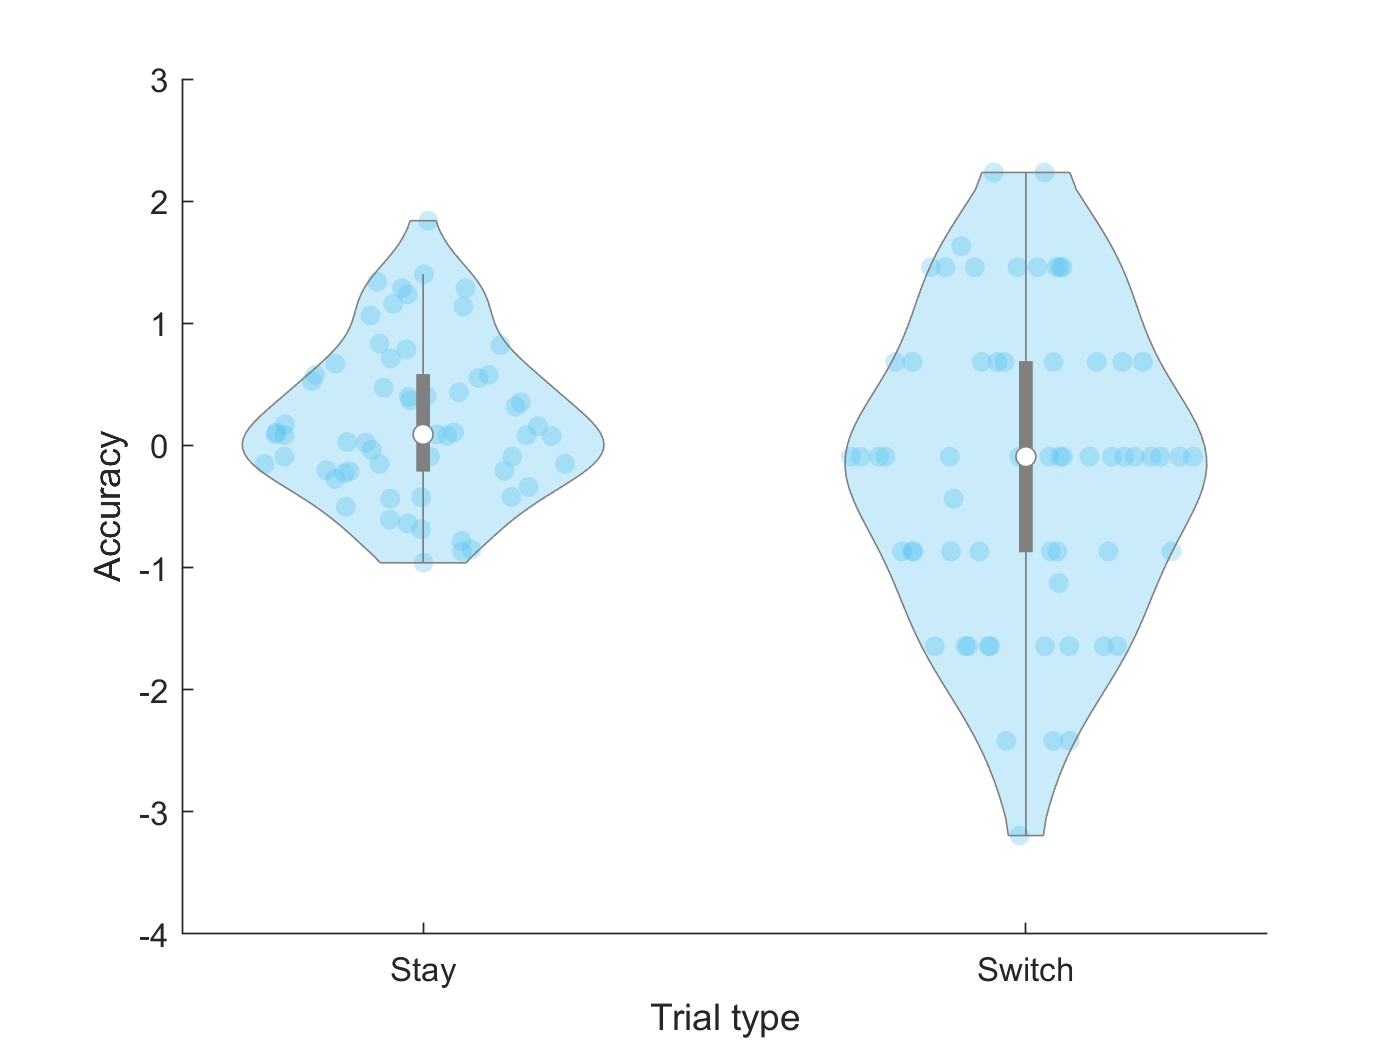


% % Plot overall switch vs nonswitch
% AccArray = grpstats(df_clean_ext,{'auto_participant_id','trial_task_type','Switch'},'nansum','DataVars',{'Correct'});
% AccArray.mean_accuracy = AccArray.nansum_Correct./AccArray.GroupCount;
% SwitchAcc = AccArray(AccArray.Switch==1,:);
% RepeatAcc = AccArray(AccArray.Switch==0,:);
% OneColumnAcc = [SwitchAcc.mean_accuracy;RepeatAcc.mean_accuracy];
% sz = size(OneColumnAcc);
% x = zeros(sz);
% x(1:183,:) = 1;
% OneColumnAcc = array2table(OneColumnAcc);
% OneColumnAcc.SwitchType = x;
% 
% g(1,1)=gramm('x',OneColumnAcc.SwitchType,'y',OneColumnAcc.OneColumnAcc,'color',OneColumnAcc.SwitchType);
% g(1,2) = copy(g(1));
% g(1,1).stat_boxplot("width",0.1);
% g(1,1).stat_violin('normalization','area','dodge',0.7,'fill','edge');
% g.set_names('x','Switch or Repeat','y','Mean Accurracy','color','Switch or Repeat');
% g.axe_property("XLim",[-0.5 1.5]);
% g(1,2).geom_jitter();
% figure
% g.draw();
% 

% %Switch vs Repeat Accurracy per Task Type
% statarray_df_clean_ext = grpstats(df_clean_ext,{'auto_participant_id','trial_task_type','occurrence','Switch'},'nansum','DataVars',{'Correct'});
% statarray_df_clean_ext.mean_accuracy = statarray_df_clean_ext.nansum_Correct./statarray_df_clean_ext.GroupCount;

% dt=gramm('x',statarray_df_clean_ext.trial_task_type,'y',statarray_df_clean_ext.mean_accuracy,'color',statarray_df_clean_ext.Switch);
% dt.stat_boxplot('width',0.15);
% dt.stat_violin('normalization','area','dodge',0.7,'fill','edge');
% dt.set_title('Switch vs Repeat Accuracy per Task Type');
% figure
% dt.draw();
% 

% Since there's an effect of task type on acc, but not occ, we will look at
% the effect of switch cost per task, and Bonferroni correct for multiple
% comparisons (among three task types = three models = p<0.0167)
df_clean_ext = convertvars(df_clean_ext, 'trial_task_type', 'categorical');
tasks = categories(df_clean_ext.trial_task_type);

for task = 1:3
  T = df_clean_ext;
  task_keep = tasks{task};
  T(~ismember(T.trial_task_type,task_keep),:)=[];
  
  sprintf('Runing stats for task %s', task_keep)
  statarray = grpstats(T,{'auto_participant_id','Switch'},'nansum','DataVars',{'Correct'});
  statarray.mean_accuracy = statarray.nansum_Correct./statarray.GroupCount;
  statarray.mean_accuracy = normalize(statarray.mean_accuracy);
  lme = fitglme(statarray,'mean_accuracy ~ Switch + (1|auto_participant_id)');
  anova(lme)
  
  figure()
  vs = violinplot(statarray.mean_accuracy,statarray.Switch,'ViolinColor',[0.301, 0.745, 0.933]);
  ylabel('Accuracy');
  xlabel('Trial type')
  xticklabels(['Stay  ';'Switch'])
  ylim([-4 3])

  clear T
   
end



%There's no switch cost for DS
%There IS a switch cost for SS and SR!!

**7.2 Switch cost in accuracy per switch type**

%Looking per switchtype
statarray_df_clean_ext = grpstats(df_clean_ext,{'auto_participant_id','Switch', 'NumSwitchtype'},'nansum','DataVars',{'Correct'});
statarray_df_clean_ext.mean_accuracy = statarray_df_clean_ext.nansum_Correct./statarray_df_clean_ext.GroupCount;

lme_light_clean = fitglme(statarray_df_clean_ext,'mean_accuracy ~ NumSwitchtype + (1|auto_participant_id)');
anova(lme_light_clean)

ans =     ANOVA marginal tests: DFMethod = 'residual'

    Term                     FStat     DF1    DF2    pValue    
    {'(Intercept)'  }        692.05    1      425    3.2207e-91
    {'NumSwitchtype'}        6.8513    1      425     0.0091739


%There is an effect of switch type on accuracy

% This is diffcult because the below lines can only keep one switch type,
% bu we need 2- 0 and whatever the numswitchtype is.
statarray_df_clean_ext = convertvars(statarray_df_clean_ext, 'NumSwitchtype', 'categorical');
types = categories(statarray_df_clean_ext.NumSwitchtype);
% 
% for type = 1:6
%   T = statarray_df_clean_ext;
%   type_keep = types{type+1};
%   T(~ismember(T.NumSwitchtype,type_keep),:)=[];
%   
%   sprintf('Runing stats for switch type %s', type_keep)
% 
% %   statarray = grpstats(T,{'auto_participant_id','Switch'});
%   lme = fitglme(statarray,'mean_accuracy ~ NumSwitchtype + (1|auto_participant_id)');
%   anova(lme)
% 
%   clear T
%    
% end

**7.3 Switch cost in RT- overall and per occurrence**

%Reminder that in the column as "Switch", 1=switch trial, 0=repeat trial
statarray_df_clean_ext = grpstats(df_clean_ext,{'Switch','auto_participant_id','trial_task_type','occurrence'},'nanmean','DataVars',{'RT_Correct'});

half=height(statarray_df_clean_ext)/2 ;
Switch=statarray_df_clean_ext.nanmean_RT_Correct(1:1505-57);
Stay=statarray_df_clean_ext.nanmean_RT_Correct(1506:2953);

% Looking just at RT Switch vs non-Switch
[H,P,CI,STATS] = ttest(Switch,Stay)

H = 0

P = 0.3930

CI =    -0.0449
    0.1141


STATS = struct with fields:
    tstat: 0.8547
       df: 811
       sd: 1.1537


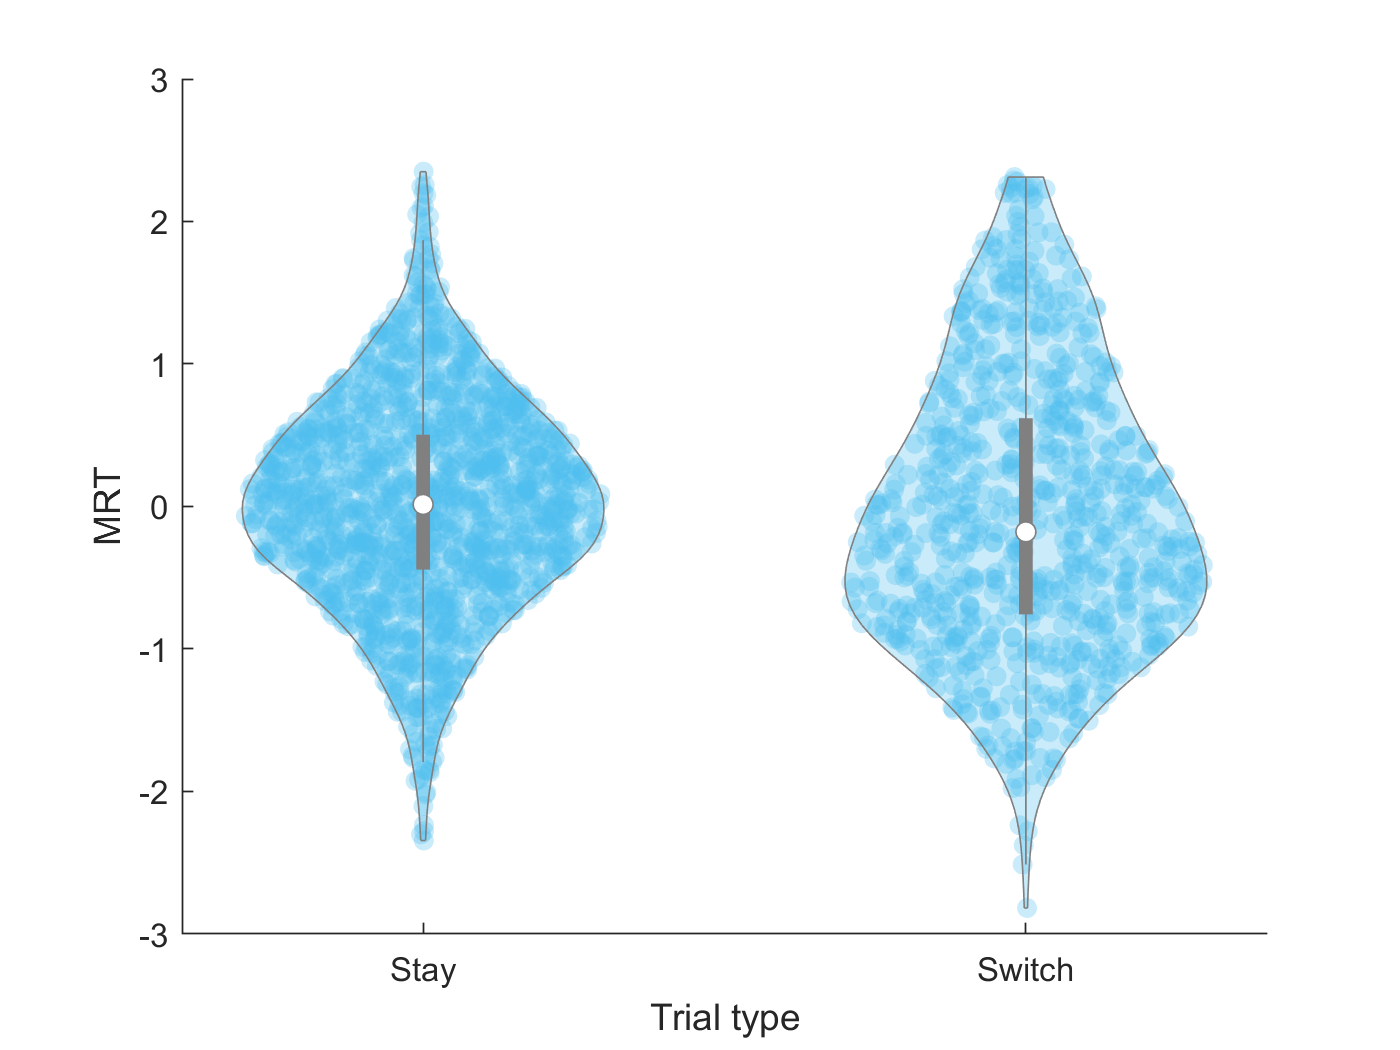

% There's no sig diff between between switch and non switch MRT

figure()
vs = violinplot(statarray_df_clean_ext.nanmean_RT_Correct,statarray_df_clean_ext.Switch,'ViolinColor',[0.301, 0.745, 0.933]);
ylabel('MRT');
xlabel('Trial type')
xticklabels(['Stay  ';'Switch'])


% Calculate switch cost in RT per occurrence- since we looked per task type
% for accuracy bc the effect of task type on acc, we'll do the same per
% occ, so p will be significant at p<0.
% As a heads up, even run in a single model with occurrence and switch as
% fixed effects, there's no effect of switch on RT. 
occurrences = unique(statarray_df_clean_ext.occurrence);
for occurrence = 1:9
  T = statarray_df_clean_ext;
  occurrence_keep = occurrences(occurrence);
  T(~ismember(T.occurrence,occurrence_keep),:)=[];
 
  sprintf('Runing stats for occurrence %s', occurrence_keep)
  lme = fitglme(T,'nanmean_RT_Correct ~ Switch + (1|auto_participant_id)');
  anova(lme)
  
  clear T
end

ans = 'Runing stats for occurrence '

ans =     ANOVA marginal tests: DFMethod = 'residual'

    Term                   FStat      DF1    DF2    pValue    
    {'(Intercept)'}         12.202    1      236    0.00056998
    {'Switch'     }        0.39815    1      236       0.52866


ans = 'Runing stats for occurrence '

ans =     ANOVA marginal tests: DFMethod = 'residual'

    Term                   FStat       DF1    DF2    pValue 
    {'(Intercept)'}          1.8409    1      283    0.17593
    {'Switch'     }        0.099558    1      283    0.75259


ans = 'Runing stats for occurrence '

ans =     ANOVA marginal tests: DFMethod = 'residual'

    Term                   FStat      DF1    DF2    pValue 
    {'(Intercept)'}         2.0182    1      289     0.1565
    {'Switch'     }        0.77782    1      289    0.37854


ans = 'Runing stats for occurrence '

ans =     ANOVA marginal tests: DFMethod = 'residual'

    Term                   FStat       DF1    DF2    pValue 
    {'(Intercept)'}        0.072616    1      290    0.78776
    {'Switch'     }        0.025533    1      290    0.87316


ans = 'Runing stats for occurrence '

ans =     ANOVA marginal tests: DFMethod = 'residual'

    Term                   FStat      DF1    DF2    pValue 
    {'(Intercept)'}        0.72351    1      283    0.39571
    {'Switch'     }         1.9372    1      283    0.16506


ans = 'Runing stats for occurrence '

ans =     ANOVA marginal tests: DFMethod = 'residual'

    Term                   FStat      DF1    DF2    pValue 
    {'(Intercept)'}        0.14336    1      281    0.70525
    {'Switch'     }         0.4991    1      281    0.48048


ans = 'Runing stats for occurrence '

ans =     ANOVA marginal tests: DFMethod = 'residual'

    Term                   FStat     DF1    DF2    pValue  
    {'(Intercept)'}        4.9171    1      278      0.0274
    {'Switch'     }        2.8741    1      278    0.091134


ans = 'Runing stats for occurrence'

ans =     ANOVA marginal tests: DFMethod = 'residual'

    Term                   FStat      DF1    DF2    pValue 
    {'(Intercept)'}         2.1703    1      259    0.14191
    {'Switch'     }        0.12956    1      259    0.71918


ans = 'Runing stats for occurrence 	'

ans =     ANOVA marginal tests: DFMethod = 'residual'

    Term                   FStat        DF1    DF2    pValue 
    {'(Intercept)'}        0.0063565    1      79     0.93666
    {'Switch'     }          0.53891    1      79     0.46506


**7.4 Switch cost in RT per switch type**

%Looking per switchtype
statarray_df_clean_ext = grpstats(df_clean_ext,{'auto_participant_id','Switch', 'NumSwitchtype'},'nanmean','DataVars',{'RT_Correct'});

lme_light_clean = fitglme(statarray_df_clean_ext,'nanmean_RT_Correct ~ NumSwitchtype + (1|auto_participant_id)');
anova(lme_light_clean)

ans =     ANOVA marginal tests: DFMethod = 'residual'

    Term                     FStat       DF1    DF2    pValue 
    {'(Intercept)'  }        0.075349    1      405    0.78384
    {'NumSwitchtype'}          1.2793    1      405     0.2587


% There's no effect of switch type on RT

% In previous versions I looked at RT incorrect as well as correct, and it
% did not change the results in previous versions, nor when lightly tested
% to this version of the analysis